clear all
x1 = 200;
x2 = 800;
[pathsSpikes tmp] = ReadPCAPaths('D:\Jazmin\MultichannelDataTanks\Cortex\');
%Obtains the paths to all the content in the specified path

[DataTable] = ReadUnitTableMultichannel("A2",1,'D:\Jazmin\MultichannelDataTanks\Cortex\V1_tracks.xlsx');
%read the excel table and saves it in a variable

[pathsSpikesMultichannel] = pathsMultichannel(tmp,pathsSpikes,DataTable);
%It creates the path to the units inlcuded in the excel table

[BST, BST_MUA] = ExtractDataMultiChannel(DataTable,pathsSpikesMultichannel); %It gets a structure wiht all the BST

UN = load ('D:\Jazmin\MultichannelDataTanks\Cortex\spiketable_Aud_Sig_revised.mat');
MUA = load ('D:\Jazmin\MultichannelDataTanks\Cortex\spiketable_Aud_Sig_MUA_revised.mat');
% UN.spiketable.unitloc = [];
SpiketableComplete = [UN.spiketable;MUA.spiketable];
%It contains structures with all the units that have an auditory response

load('D:\Jazmin\MultichannelDataTanks\Cortex\CompleteSpikes_MUA.mat')
load('D:\Jazmin\MultichannelDataTanks\Cortex\CompleteSpikes.mat')

%Add a sweep identifier 1 to 400 for each trial
for i = 1:1:size(BST,1)
    y = 0;
    for j = 2:1:3060
        if BST(i).bst.Epocs.Values.wfrq(j-1,1) == 100 && BST(i).bst.Epocs.Values.wfrq(j,1) > 100
            BST(i).bst.Epocs.Values.swee(j:j+399,1) = [1:400]';
        end
    end
end


%These section creates a vector for each recording with the row number
%where each kind of stimulus of interest happen and saves it in a structure
for i = 1:1:size(BST,1)
    ODDTrialIndex = zeros(80,1);
    ODDTrialIndexP = zeros(80,1);
    CTR_ASCTrialIndex = zeros(160,1);
    CTRMSTrialIndex_F1 = zeros(160,1);
    STDMSTrialIndex = zeros(80,1);
    STDTrialIndex = zeros(80,1);
    AllSTDTrialIndex = zeros(360,1);
    AllSTDTrialIndexP = zeros(360,1);
    n = 1;
    m = 1;
    mn = 1;
    mm = 1;
    mp = 1;
    k = 1;
    p = 1;
    pp = 1;
    t = 1;
    tt = 1;
    q = 1;
    r = 1;
    s = 0;
    for j = 1:1:3060
        if isempty(cell2mat(BST(i).bst.Epocs.Values.type(j,1)))
            s = s + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'DEV')
            ODDtrials(n,1) = BST(i).bst.Epocs.Values.swee(j,1);
            ODDTrialIndex(n,1) = j;
            n = n + 1;
            %        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'DEV')
            %     %             ODDtrials(n,1) = BST(i).bst.Epocs.Values.swee(j,1) + 1;
            %                 ODDTrialIndexP(q,1) = j;
            %                 q = q + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-ASC-F1');
            CTR_ASC_F1trials(m,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_ASC_F1TrialIndex(m,1) = j;
            m = m + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-ASC-F2');
            CTR_ASC_F2trials(mn,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_ASC_F2TrialIndex(mn,1) = j;
            mn = mn + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-DES-F1');
            CTR_DESC_F1trials(mm,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_DESC_F1TrialIndex(mm,1) = j;
            mm = mm + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'CASC-DES-F2');
            CTR_DESC_F2trials(mp,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTR_DESC_F2TrialIndex(mp,1) = j;
            mp = mp + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'MS-F1');
            CTRMStrials_F1(t,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTRMSTrialIndex_F1(t,1) = j;
            t = t + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'MS-F2');
            CTRMStrials_F2(tt,1) = BST(i).bst.Epocs.Values.swee(j,1);
            CTRMSTrialIndex_F2(tt,1) = j;
            tt = tt + 1;
        elseif contains(string(BST(i).bst.Epocs.Values.type(j,1)),'ODD') && contains(string(BST(i).bst.Epocs.Values.type(j,1)),'STD')
            STDtrials(k,1) = BST(i).bst.Epocs.Values.swee(j,1);
            STDTrialIndex(k,1) = j;
            k = k + 1;
        end

    end

    for iii = 21:1:1740

        % if isempty(cell2mat(BST(i).bst.Epocs.Values.type(iii,1))) && BST(i).bst.Epocs.Values.wfrq(iii,1)>100
        % 
        %     AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
        %     AllSTDTrialIndex(p,1) = iii;
        %     p = p + 1;
       if contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDR') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'')
           AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndex(p,1) = iii;
            p = p + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDR') | contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'STD') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'ODDR')
            AllSTDtrials(p,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndex(p,1) = iii;
            p = p + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDP') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'')
            AllSTDtrialsP(pp,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndexP(pp,1) = iii;
            pp = pp + 1;
       elseif contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'ODDP') | contains(string(BST(i).bst.Epocs.Values.type(iii,1)),'STD') && contains(string(BST(i).bst.Epocs.Values.type(iii-1,1)),'ODDP')
            AllSTDtrialsP(pp,1) = BST(i).bst.Epocs.Values.swee(iii,1);
            AllSTDTrialIndexP(pp,1) = iii;
            pp = pp + 1;
        end
    end

    ODDTrialIndexP = [ODDTrialIndex(41:80);ODDTrialIndex(121:160)];
    ODDTrialIndex = [ODDTrialIndex(1:40);ODDTrialIndex(81:120)];
    STDTrialIndexP = [ STDTrialIndex(41:80); STDTrialIndex(121:160)];
    STDTrialIndex = [ STDTrialIndex(1:40); STDTrialIndex(81:120)];

    ODDtrialsP = [ODDtrials(41:80);ODDtrials(121:160)];
    ODDtrials = [ODDtrials(1:40);ODDtrials(81:120)];
    STDtrialsP = [ STDtrials(41:80); STDtrials(121:160)];
    STDtrials = [ STDtrials(1:40); STDtrials(81:120)];

    ODDTrialIndexS = struct('ODDTrialIndex', ODDTrialIndex);
    ODDTrialIndexPS = struct('ODDTrialIndexP', ODDTrialIndexP);
    CTR_DESC_F2TrialIndexS = struct('CTRTrialIndex', CTR_DESC_F2TrialIndex);
    CTR_DESC_F1TrialIndexS = struct('CTRTrialIndex', CTR_DESC_F1TrialIndex);
    CTR_ASC_F1TrialIndexS = struct('CTRTrialIndex', CTR_ASC_F1TrialIndex);
    CTR_ASC_F2TrialIndexS = struct('CTRTrialIndex', CTR_ASC_F2TrialIndex);
    CTRMSTrialIndexS_F1 = struct('CTRMSTrialIndex', CTRMSTrialIndex_F1);
    CTRMSTrialIndexS_F2 = struct('CTRMSTrialIndex', CTRMSTrialIndex_F2);
    STDTrialIndexS = struct('STDTrialIndex', STDTrialIndex);
    STDTrialIndexSP = struct('STDTrialIndex', STDTrialIndexP);
    AllSTDTrialIndexS = struct('AllSTDTrialIndex', AllSTDTrialIndex);
    AllSTDTrialIndexPS = struct('AllSTDTrialIndexP', AllSTDTrialIndexP);

    ODDTrialsS = struct('ODDtrials', ODDtrials);
    CTR_ASC_F1TrialsS = struct('CTRtrials', CTR_ASC_F1trials);
    CTR_ASC_F2TrialsS = struct('CTRtrials', CTR_ASC_F2trials);
    CTR_DESC_F1TrialsS = struct('CTRtrials', CTR_DESC_F1trials);
    CTR_DESC_F2TrialsS = struct('CTRtrials', CTR_DESC_F2trials);
    CTRMSTrialsS_F1 = struct('CTRMStrials', CTRMStrials_F1);
    CTRMSTrialsS_F2 = struct('CTRMStrials', CTRMStrials_F2);
    STDTrialsS = struct('STDtrials', STDtrials);
    STDTrialsSP = struct('STDtrials', STDtrialsP);
    ODDTrialsPS = struct('ODDtrialsP', ODDtrialsP);
    AllSTDTrialsS = struct('AllSTDtrials', AllSTDtrials);
    AllSTDTrialsPS = struct('AllSTDtrialPs', AllSTDtrialsP);

    ODDTrialIndexComplete(:,i) = ODDTrialIndexS;
    ODDTrialIndexCompleteP(:,i) = ODDTrialIndexPS;
    CTR_ASC_F1TrialIndexComplete(:,i) = CTR_ASC_F1TrialIndexS;
    CTR_ASC_F2TrialIndexComplete(:,i) = CTR_ASC_F2TrialIndexS;
    CTR_DESC_F1TrialIndexComplete(:,i) = CTR_DESC_F1TrialIndexS;
    CTR_DESC_F2TrialIndexComplete(:,i) = CTR_DESC_F2TrialIndexS;
    CTRMSTrialIndex_F1Complete(:,i) = CTRMSTrialIndexS_F1;
    CTRMSTrialIndex_F2Complete(:,i) = CTRMSTrialIndexS_F2;
    STDTrialIndexComplete(:,i) = STDTrialIndexS;
    STDTrialIndexComplete_P(:,i) = STDTrialIndexSP;
    AllSTDTrialIndexComplete(:,i) = AllSTDTrialIndexS;
    AllSTDTrialIndexCompleteP(:,i) = AllSTDTrialIndexPS;

    ODDTrialsComplete(:,i) = ODDTrialsS;
    ODDTrialsCompleteP(:,i) = ODDTrialsPS;
    CTR_ASC_F1TrialsComplete(:,i) = CTR_ASC_F1TrialsS;
    CTR_ASC_F2TrialsComplete(:,i) = CTR_ASC_F2TrialsS;
    CTR_DESC_F1TrialsComplete(:,i) = CTR_DESC_F1TrialsS;
    CTR_DESC_F2TrialsComplete(:,i) = CTR_DESC_F2TrialsS;
    CTRMSTrialsComplete_F1(:,i) = CTRMSTrialsS_F1;
    CTRMSTrialsComplete_F2(:,i) = CTRMSTrialsS_F2;
    STDTrialsComplete(:,i) = STDTrialsS;
    STDTrialsComplete_P(:,i) = STDTrialsSP;
    AllSTDTrialsComplete(:,i) = AllSTDTrialsS;
    AllSTDTrialsCompleteP(:,i) = AllSTDTrialsPS;
end

for ii = 1:size(BST_MUA,1)
    AllSTDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialIndexCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
    CTRTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    CTRMSTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialIndexComplete_P(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialIndexComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialIndexCompleteP(ii).path = pathsSpikesMultichannel(ii,1);

    ODDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    ODDTrialsCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
    CTRTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    CTRMSTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    STDTrialsComplete_P(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialsComplete(ii).path = pathsSpikesMultichannel(ii,1);
    AllSTDTrialsCompleteP(ii).path = pathsSpikesMultichannel(ii,1);
end

AllSpikeTable = [CompleteSpikes;CompleteSpikes_MUA];

n=1;
for i = 1:size(AllSpikeTable,1)
    if AllSpikeTable.layer(i) == 6
        Layer6(n,:) = AllSpikeTable(i,:);
        n = n+1;
    end
end

AllSpikeTable = Layer6;

a = 1;
b = 1;
c = 1;
d = 1;
for i = 1:size(AllSpikeTable,1)
    if AllSpikeTable.Auditory(i) == 1
        AllSpikeTable_Auditory(a,:) = AllSpikeTable(i,:);
        a = a + 1;
    end
    if AllSpikeTable.AuditoryP(i) == 1
        AllSpikeTable_AuditoryP(b,:) = AllSpikeTable(i,:);
        b = b + 1;
    end
    if AllSpikeTable.Significance(i) == 1
        AllSpikeTable_Significance(c,:) = AllSpikeTable(i,:);
        c = c + 1;
    end
    if AllSpikeTable.SignificanceP(i) == 1
        AllSpikeTable_SignificanceP(d,:) = AllSpikeTable(i,:);
        d = d + 1;
    end
end

for i = 1:size(AllSpikeTable_Significance,1)
    AllSTDtrialsRest(i).STDtrials = setdiff(AllSTDTrialsComplete(1).AllSTDtrials(1:360),STDTrialsComplete(1).STDtrials(1:40));
    AllSTDtrialsRest_P(i).STDtrialsP = setdiff(AllSTDTrialsCompleteP(1).AllSTDtrialPs(1:360),STDTrialsComplete_P(1).STDtrials(1:40));
    AllCTRMSTrials=(1:400);
    MStrials = setdiff(AllCTRMSTrials',CTRMSTrialsComplete_F1(1).CTRMStrials);
    MStrialsRest(i).MStrials = setdiff(MStrials,CTRMSTrialsComplete_F2(1).CTRMStrials);
    AllCTRCASCascTrials=(1:400);
    CASCasctrials = setdiff(AllCTRCASCascTrials',CTR_ASC_F1TrialsComplete(1).CTRtrials);
    CASCasctrialsRest(i).CASCasctrials = setdiff(CASCasctrials,CTR_ASC_F2TrialsComplete(1).CTRtrials);
    AllCTRCASCdesTrials=(1:400);
    CASCdestrials = setdiff(AllCTRCASCdesTrials',CTR_DESC_F1TrialsComplete(1).CTRtrials);
    CASCdestrialsRest(i).CASCdes = setdiff(CASCdestrials,CTR_DESC_F2TrialsComplete(1).CTRtrials);
end

DEVcount = zeros(40,1);
    for j = 1:size(AllSpikeTable_Significance,1)
        for k = 1:1:40
            DEVtimesASC = table2array(AllSpikeTable_Significance.spikes{j,1}(k,3));
            for i = 1:size(DEVtimesASC{1,1},1)
                if DEVtimesASC{1,1}(i) >= 200 && DEVtimesASC{1,1}(i) <= 800
                    DEVcount(k) = DEVcount(k) + 1;
                end
            end
    
            DEVtimesDES = table2array(AllSpikeTable_Significance.spikes{j,1}(k,8));
            for i = 1:size(DEVtimesDES{1,1},1)
                if DEVtimesDES{1,1}(i) >= 200 && DEVtimesDES{1,1}(i) <= 800
                    DEVcount(k) = DEVcount(k) + 1;
                end
            end
        end
    end

STDcount = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        STDtimesASC = table2array(AllSpikeTable_Significance.spikes{j,1}(k,2));
        for i = 1:size(STDtimesASC{1,1},1)
            if STDtimesASC{1,1}(i) >= 200 && STDtimesASC{1,1}(i) <= 800
                STDcount(k) = STDcount(k) + 1;
            end
        end

        STDtimesDES = table2array(AllSpikeTable_Significance.spikes{j,1}(k,7));
        for i = 1:size(STDtimesDES{1,1},1)
            if STDtimesDES{1,1}(i) >= 200 && STDtimesDES{1,1}(i) <= 800
                STDcount(k) = STDcount(k) + 1;
            end
        end
    end
end


STDcountRest = zeros(640,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:640
        STDtimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,1));
        for i = 1:size(STDtimesRest{1,1},1)
            if STDtimesRest{1,1}(i) >= 200 && STDtimesRest{1,1}(i) <= 800
                STDcountRest(k) = STDcountRest(k) + 1;
            end
        end
    end
end
STDcountRest = STDcountRest(1:320)+STDcountRest(321:640);

DEVcount_P = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        DEVtimesASC_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,6));
        for i = 1:size(DEVtimesASC_P{1,1},1)
            if DEVtimesASC_P{1,1}(i) >= 200 && DEVtimesASC_P{1,1}(i) <= 800
                DEVcount_P(k) = DEVcount_P(k) + 1;
            end
        end

        DEVtimesDES_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,10));
        for i = 1:size(DEVtimesDES_P{1,1},1)
            if DEVtimesDES_P{1,1}(i) >= 200 && DEVtimesDES_P{1,1}(i) <= 800
                DEVcount_P(k) = DEVcount_P(k) + 1;
            end
        end
    end
end

STDcount_P = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        STDtimesASC_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,5));
        for i = 1:size(STDtimesASC_P{1,1},1)
            if STDtimesASC_P{1,1}(i) >= 200 && STDtimesASC_P{1,1}(i) <= 800
                STDcount_P(k) = STDcount_P(k) + 1;
            end
        end

        STDtimesDES_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,9));
        for i = 1:size(STDtimesDES_P{1,1},1)
            if STDtimesDES_P{1,1}(i) >= 200 && STDtimesDES_P{1,1}(i) <= 800
                STDcount_P(k) = STDcount_P(k) + 1;
            end
        end
    end
end

STDcountRest_P = zeros(640,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:640
        STDtimesRest_P = table2array(AllSpikeTable_Significance.spikes{j,1}(k,4));
        for i = 1:size(STDtimesRest_P{1,1},1)
            if STDtimesRest_P{1,1}(i) >= 200 && STDtimesRest_P{1,1}(i) <= 800
                STDcountRest_P(k) = STDcountRest_P(k) + 1;
            end
        end
    end
end
STDcountRest_P = STDcountRest_P(1:320)+STDcountRest_P(321:640);

MScount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,13));
        for i = 1:size(MStimes_F1{1,1},1)
            if MStimes_F1{1,1}(i) >= 200 && MStimes_F1{1,1}(i) <= 800
                MScount_F1(k) = MScount_F1(k) + 1;
            end
        end
    end
end

MScount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,12));
        for i = 1:size(MStimes_F2{1,1},1)
            if MStimes_F2{1,1}(i) >= 200 && MStimes_F2{1,1}(i) <= 800
                MScount_F2(k) = MScount_F2(k) + 1;
            end
        end
    end
end

MScount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        MStimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,11));
        for i = 1:size(MStimesRest{1,1},1)
            if MStimesRest{1,1}(i) >= 200 && MStimesRest{1,1}(i) <= 800
                MScount_rest(k) = MScount_rest(k) + 1;
            end
        end
    end
end

CASCasccount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,15));
        for i = 1:size(CASCasctimes_F1{1,1},1)
            if CASCasctimes_F1{1,1}(i) >= 200 && CASCasctimes_F1{1,1}(i) <= 800
                CASCasccount_F1(k) = CASCasccount_F1(k) + 1;
            end
        end
    end
end

CASCasccount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,16));
        for i = 1:size(CASCasctimes_F2{1,1},1)
            if CASCasctimes_F2{1,1}(i) >= 200 && CASCasctimes_F2{1,1}(i) <= 800
                CASCasccount_F2(k) = CASCasccount_F2(k) + 1;
            end
        end
    end
end

CASCasccount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCasctimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,14));
        for i = 1:size(CASCasctimesRest{1,1},1)
            if CASCasctimesRest{1,1}(i) >= 200 && CASCasctimesRest{1,1}(i) <= 800
                CASCasccount_rest(k) = CASCasccount_rest(k) + 1;
            end
        end
    end
end

CASCdescount_F1 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,19));
        for i = 1:size(CASCdestimes_F1{1,1},1)
            if CASCdestimes_F1{1,1}(i) >= 200 && CASCdestimes_F1{1,1}(i) <= 800
                CASCdescount_F1(k) = CASCdescount_F1(k) + 1;
            end
        end
    end
end

CASCdescount_F2 = zeros(40,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,18));
        for i = 1:size(CASCdestimes_F2{1,1},1)
            if CASCdestimes_F2{1,1}(i) >= 200 && CASCdestimes_F2{1,1}(i) <= 800
                CASCdescount_F2(k) = CASCdescount_F2(k) + 1;
            end
        end
    end
end

CASCdescount_rest = zeros(320,1);
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCdestimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,17));
        for i = 1:size(CASCdestimesRest{1,1},1)
            if CASCdestimesRest{1,1}(i) >= 200 && CASCdestimesRest{1,1}(i) <= 800
                CASCdescount_rest(k) = CASCdescount_rest(k) + 1;
            end
        end
    end
end

n = size(AllSpikeTable_Significance,1);
spike_counts = zeros(1,400);
for i = 1:40
spike_counts(1,ODDTrialsComplete(1).ODDtrials(i)) = DEVcount(i,1)./n;
spike_counts(1,STDTrialsComplete(1).STDtrials(i)) = STDcount(i,1)./n;
end

for j = 1:320
spike_counts(1,AllSTDtrialsRest(1).STDtrials(j)) = STDcountRest(j,1)./n;
end

spike_counts_P = zeros(1,400);
for i = 1:40
spike_counts_P(1,ODDTrialsCompleteP(1).ODDtrialsP(i)) = DEVcount_P(i,1)./n;
spike_counts_P(1,STDTrialsComplete_P(1).STDtrials(i)) = STDcount_P(i,1)./n;
end

for j = 1:320
spike_counts_P(1,AllSTDtrialsRest_P(1).STDtrialsP(j)) = STDcountRest_P(j,1)./n;
end


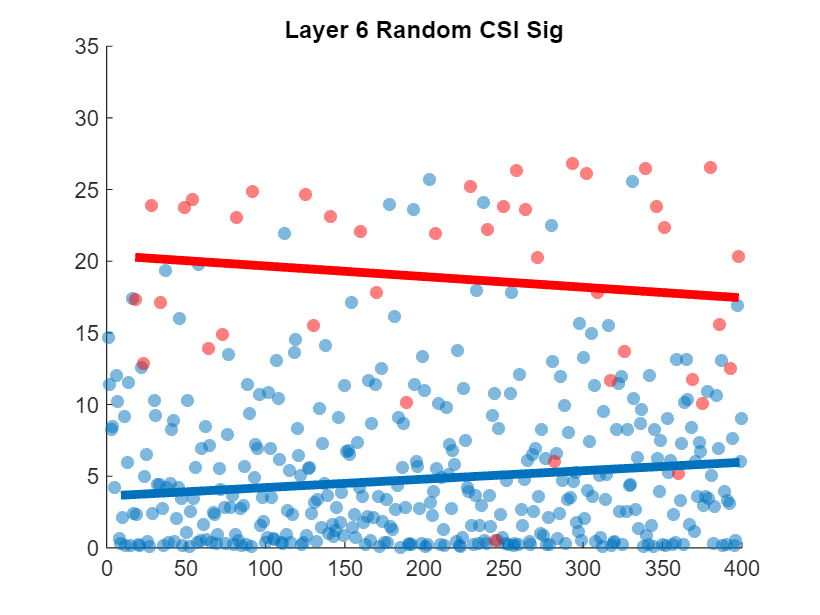

n = size(AllSpikeTable_Significance,1);
figure
title ('Layer 6 Random CSI Sig')
hold on
scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
ylim([0,35])

% % scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./max(STDcount),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./max(STDcountRest),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % s=findobj(gca,'Type','Scatter');
% % X = s.XData;
% % Y = s.YData;
% % f1 = polyfit(X,Y,3)
% % y1 = polyval(f1,X);
% % plot(X,y1)
% % scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% % f2 = polyfit(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),3)
% % y2 = polyval(f2,ODDTrialsComplete(1).ODDtrials(1:40));
% % plot(ODDTrialsComplete(1).ODDtrials(1:40),y2)

        p = polyfit(STDTrialsComplete(1).STDtrials(1:40), STDcount./n, 1);
        px = [min(STDTrialsComplete(1).STDtrials(1:40)) max(STDTrialsComplete(1).STDtrials(1:40))];
        py = polyval(p, px);
        % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);

        p_r = polyfit(AllSTDtrialsRest(1).STDtrials, STDcountRest./n, 1);
        px_r = [min(AllSTDtrialsRest(1).STDtrials) max(AllSTDtrialsRest(1).STDtrials)];
        py_r = polyval(p_r, px_r);
        % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');


        P= (p+p_r)./2;
        Px = (px+px_r)./2;
        Py = polyval(P, Px);
        plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);


        p = polyfit(ODDTrialsComplete(1).ODDtrials(1:40),DEVcount./n, 1);
        px = [min(ODDTrialsComplete(1).ODDtrials(1:40)) max(ODDTrialsComplete(1).ODDtrials(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

% x = 0:400;
% y_dev = 5.3157 + (0.0033033) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])

% y_std = 2.7570 + (0.0021288) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])

cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer6_Sig_Random_SpkPerTrial_STD_DEV.tif');
saveas(gcf,['Layer6_Sig_Random_SpkPerTrial_STD_DEV.fig']);
saveas(gcf,['Layer6_Sig_Random_SpkPerTrial_STD_DEV.pdf']);

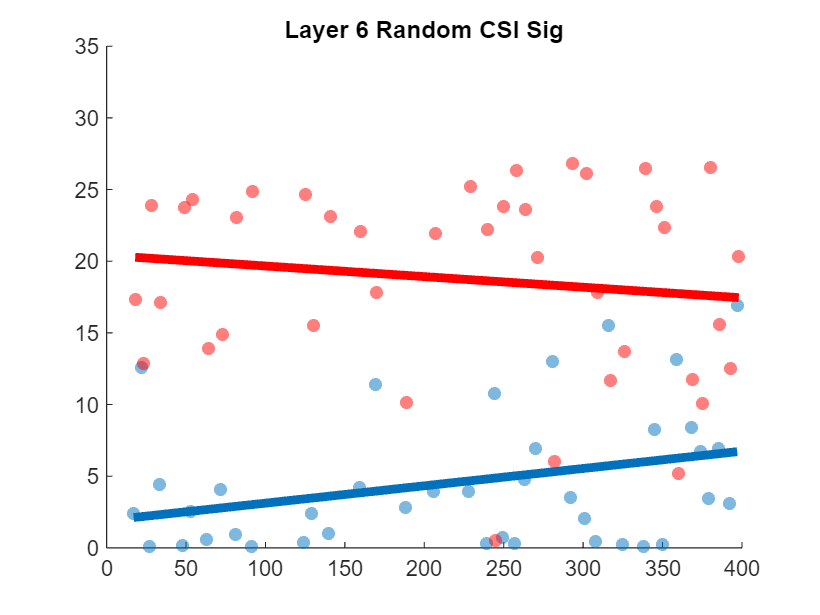

n = size(AllSpikeTable_Significance,1);
figure
title ('Layer 6 Random CSI Sig')
hold on
scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
ylim([0,35])

% % scatter(STDTrialsComplete(1).STDtrials(1:40), STDcount./max(STDcount),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % scatter(AllSTDtrialsRest(1).STDtrials, STDcountRest./max(STDcountRest),'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% % s=findobj(gca,'Type','Scatter');
% % X = s.XData;
% % Y = s.YData;
% % f1 = polyfit(X,Y,3)
% % y1 = polyval(f1,X);
% % plot(X,y1)
% % scatter(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% % f2 = polyfit(ODDTrialsComplete(1).ODDtrials(1:40), DEVcount./max(DEVcount),3)
% % y2 = polyval(f2,ODDTrialsComplete(1).ODDtrials(1:40));
% % plot(ODDTrialsComplete(1).ODDtrials(1:40),y2)

        p = polyfit(STDTrialsComplete(1).STDtrials(1:40), STDcount./n, 1);
        px = [min(STDTrialsComplete(1).STDtrials(1:40)) max(STDTrialsComplete(1).STDtrials(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);

        % p_r = polyfit(AllSTDtrialsRest(1).STDtrials, STDcountRest./n, 1);
        % px_r = [min(AllSTDtrialsRest(1).STDtrials) max(AllSTDtrialsRest(1).STDtrials)];
        % py_r = polyval(p_r, px_r);
        % % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');

        % 
        % P= (p+p_r)./2;
        % Px = (px+px_r)./2;
        % Py = polyval(P, Px);
        % plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);


        p = polyfit(ODDTrialsComplete(1).ODDtrials(1:40),DEVcount./n, 1);
        px = [min(ODDTrialsComplete(1).ODDtrials(1:40)) max(ODDTrialsComplete(1).ODDtrials(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

% x = 0:400;
% y_dev = 5.3157 + (0.0033033) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])

% y_std = 2.7570 + (0.0021288) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])

cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer6_Sig_Random_SpkPerTrial_STD_B_DEV.tif');
saveas(gcf,['Layer6_Sig_Random_SpkPerTrial_STD_B_DEV.fig']);
saveas(gcf,['Layer6_Sig_Random_SpkPerTrial_STD_B_DEV.pdf']);

n = size(AllSpikeTable_Significance,1);
Nor=max(STDcountRest./n);
err=((STDcountRest./n)/Nor)./sqrt(size(STDcountRest,1))

err =     0.0320
    0.0247
    0.0179
    0.0183
    0.0091
    0.0261
    0.0222
    0.0014
    0.0006
    0.0046


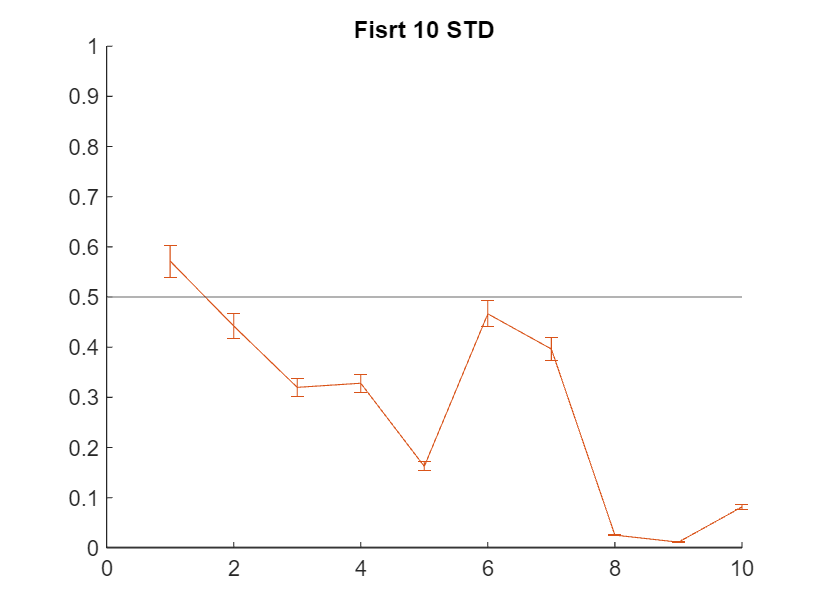

figure
% scatter(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./n)/Nor,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
hold on
plot(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./n)/Nor)
errorbar(AllSTDtrialsRest(1).STDtrials(1:10), (STDcountRest(1:10)./n)/Nor,err(1:10))
yline((min(STDcountRest./n))/Nor)
yline(0.5)
title ('Fisrt 10 STD')
ylim([0,1])
xlim([0,10])

% figure
% scatter(ODDTrialsCompleteP(1).ODDtrialsP(1:40), DEVcount_P./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
% title ('CA1 Periodic CSI Sig')
% hold on
% scatter(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% scatter(AllSTDtrialsRest, STDcountRest,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% hold off
% cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.tif');
% saveas(gcf,['HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.fig']);
% saveas(gcf,['HIP_Sig_Periodic_SpkPerTrial_STDbefore_DEV.pdf']);

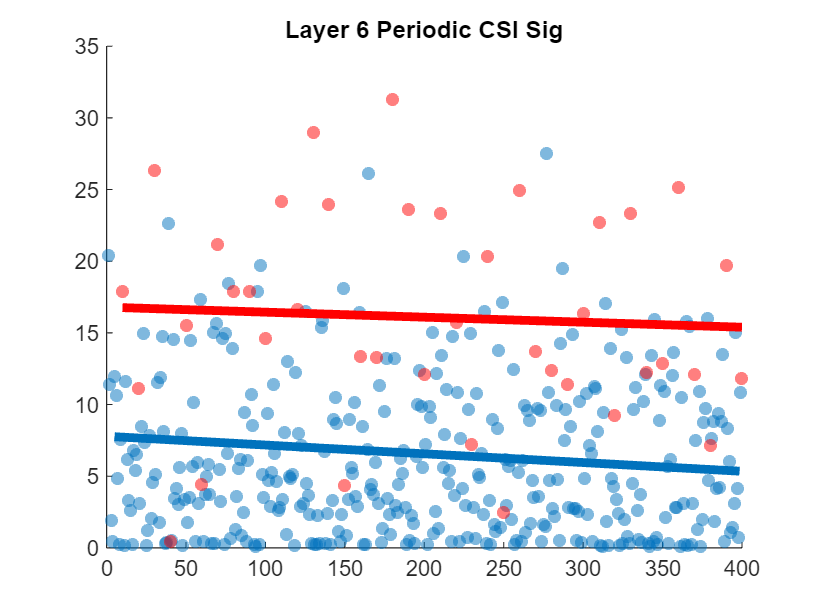

n = size(AllSpikeTable_Significance,1);
figure
title ('Layer 6 Periodic CSI Sig')
hold on
scatter(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(AllSTDtrialsRest_P(1).STDtrialsP, STDcountRest_P./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(ODDTrialsCompleteP(1).ODDtrialsP(1:40), DEVcount_P./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
ylim([0,35])
        p = polyfit(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./n, 1);
        px = [min(STDTrialsComplete_P(1).STDtrials(1:40)) max(STDTrialsComplete_P(1).STDtrials(1:40))];
        py = polyval(p, px);
        % plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);

        p_r = polyfit(AllSTDtrialsRest_P(1).STDtrialsP, STDcountRest_P./n, 1);
        px_r = [min(AllSTDtrialsRest_P(1).STDtrialsP) max(AllSTDtrialsRest_P(1).STDtrialsP)];
        py_r = polyval(p_r, px_r);
        % plot(px_r, py_r, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');

        P= (p+p_r)./2;
        Px = (px+px_r)./2;
        Py = polyval(P, Px);
        plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);


        p = polyfit(ODDTrialsCompleteP(1).ODDtrialsP(1:40),DEVcount_P./n, 1);
        px = [min(ODDTrialsCompleteP(1).ODDtrialsP(1:40)) max(ODDTrialsCompleteP(1).ODDtrialsP(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

% x = 0:400;
% y_dev = 5.9515 + (0.0018401) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])
% 
% y_std = 3.4611 + (0.00031385) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])
% 
% hold off
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer6_Sig_Periodic_SpkPerTrial_STD_DEV.tif');
saveas(gcf,['Layer6_Sig_Periodic_SpkPerTrial_STD_DEV.fig']);
saveas(gcf,['Layer6_Sig_Periodic_SpkPerTrial_STD_DEV.pdf']);

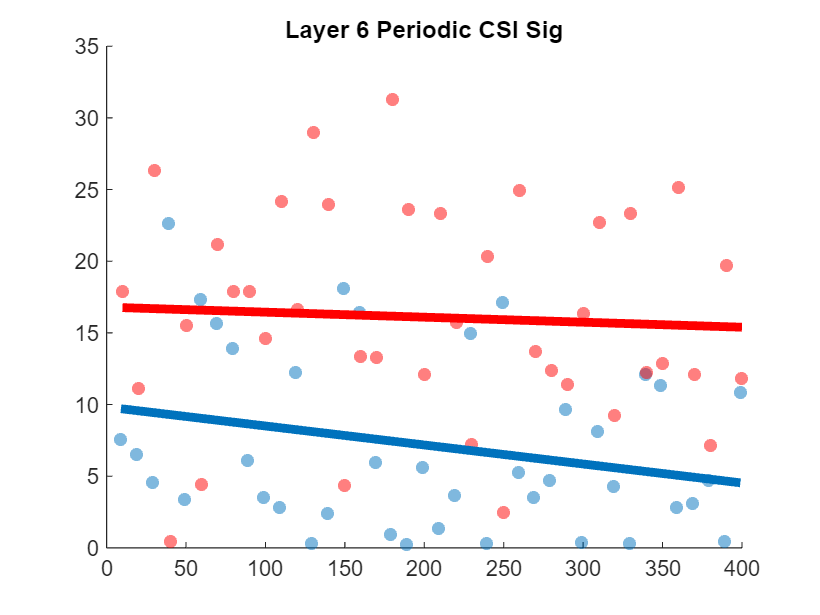

n = size(AllSpikeTable_Significance,1);
figure
title ('Layer 6 Periodic CSI Sig')
hold on
scatter(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
% scatter(AllSTDtrialsRest_P(1).STDtrialsP, STDcountRest_P./n,'filled','MarkerFaceColor',[0 0.4470 0.7410],'MarkerFaceAlpha',.5)
scatter(ODDTrialsCompleteP(1).ODDtrialsP(1:40), DEVcount_P./n,'filled','MarkerFaceColor',[1 0 0],'MarkerFaceAlpha',.5)
ylim([0,35])
        p = polyfit(STDTrialsComplete_P(1).STDtrials(1:40), STDcount_P./n, 1);
        px = [min(STDTrialsComplete_P(1).STDtrials(1:40)) max(STDTrialsComplete_P(1).STDtrials(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);
        
        % p_r = polyfit(AllSTDtrialsRest_P(1).STDtrialsP, STDcountRest_P./n, 1);
        % px_r = [min(AllSTDtrialsRest_P(1).STDtrialsP) max(AllSTDtrialsRest_P(1).STDtrialsP)];
        % py_r = polyval(p_r, px_r);
        % % plot(px_r, py_r, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--');
        % 
        % P= (p+p_r)./2;
        % Px = (px+px_r)./2;
        % Py = polyval(P, Px);
        % plot(Px, Py, 'LineWidth', 4,'Color',[0 0.4470 0.7410]);


        p = polyfit(ODDTrialsCompleteP(1).ODDtrialsP(1:40),DEVcount_P./n, 1);
        px = [min(ODDTrialsCompleteP(1).ODDtrialsP(1:40)) max(ODDTrialsCompleteP(1).ODDtrialsP(1:40))];
        py = polyval(p, px);
        plot(px, py, 'LineWidth', 4,'Color',[1 0 0]);

% x = 0:400;
% y_dev = 5.9515 + (0.0018401) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])
% 
% y_std = 3.4611 + (0.00031385) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])
% 
% hold off
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer6_Sig_Periodic_SpkPerTrial_STD_B_DEV.tif');
saveas(gcf,['Layer6_Sig_Periodic_SpkPerTrial_STD_B_DEV.fig']);
saveas(gcf,['Layer6_Sig_Periodic_SpkPerTrial_STD_B_DEV.pdf']);

n = size(AllSpikeTable_Significance,1);
%ODD R vs P
% ODD R referencia
Trials = [ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n];
Group = [ones(40,1); ones(360,1)*2; ones(40,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           20.407       1.8039     11.313    1.3081e-27
    Tiempo            -0.0074063    0.0070895    -1.0447       0.29649
    Grupo_2              -15.444       1.8944    -8.1527    1.3878e-15
    Grupo_3              -3.6119       2.5267    -1.4295       0.15326
    Grupo_4              -14.224       1.8945    -7.5083    1.6155e-13
    Tiempo:Grupo_2     0.0085479    0.0075273     1.1356       0.25647
    Tiempo:Grupo_3     0.0039061     0.010335    0.37795       0.70557
    Tiempo:Gru

anova(modelo, 'summary') % Prueba de significancia de los efectos

ans = 5×5 table
                   SumSq     DF     MeanSq       F         pValue  
                   ______    ___    ______    _______    __________

    Total           34200    799    42.804                         
    Model           10328      7    1475.4     48.947    7.1846e-58
    . Linear        10282      4    2570.5     85.278    3.0397e-60
    . Nonlinear    45.746      3    15.249    0.50589       0.67831
    Residual        23873    792    30.142                         


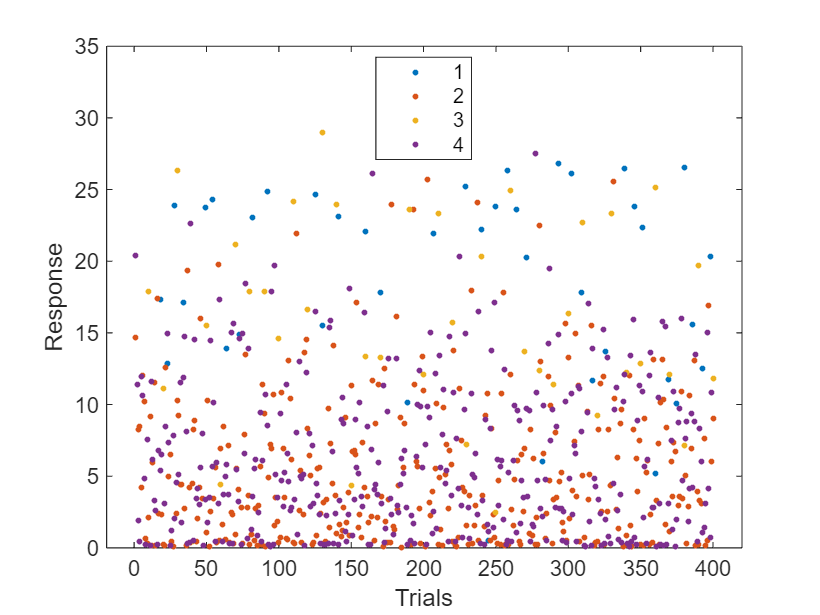


%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           20.407       1.8039     11.313    1.3081e-27
    Tiempo            -0.0074063    0.0070895    -1.0447       0.29649
    Grupo_2              -15.444       1.8944    -8.1527    1.3878e-15
    Grupo_3              -3.6119       2.5267    -1.4295       0.15326
    Grupo_4              -14.224       1.8945    -7.5083    1.6155e-13
    Tiempo:Grupo_2     0.0085479    0.0075273     1.1356       0.25647
    Tiempo:Grupo_3     0.0039061     0.010335    0.37795       0.70557
    Tiemp

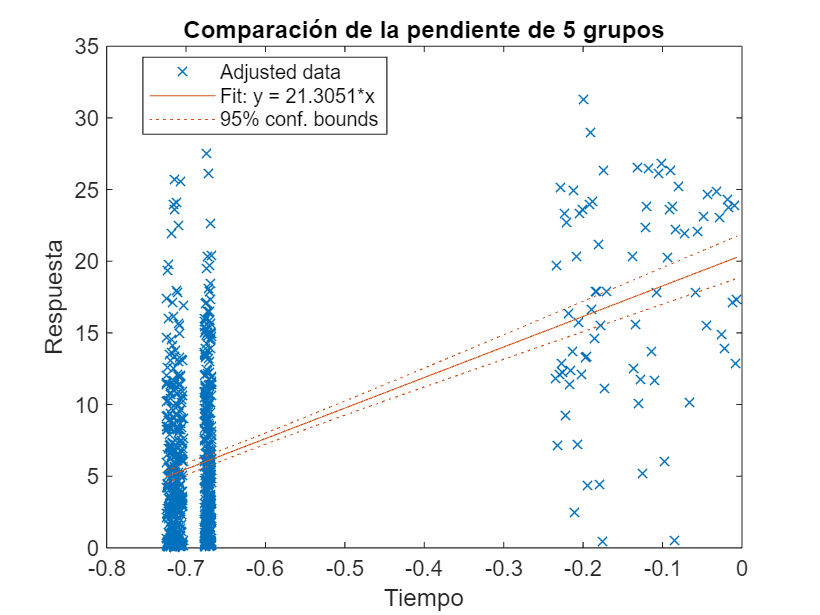

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% STD R referencia
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsComplete(1).ODDtrials(1:40);ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [STDcount./n;STDcountRest./n;DEVcount./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n];
Group = [ones(360,1)*2; ones(40,1); ones(40,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           20.407       1.8039     11.313    1.3081e-27
    Tiempo            -0.0074063    0.0070895    -1.0447       0.29649
    Grupo_2              -15.444       1.8944    -8.1527    1.3878e-15
    Grupo_3              -3.6119       2.5267    -1.4295       0.15326
    Grupo_4              -14.224       1.8945    -7.5083    1.6155e-13
    Tiempo:Grupo_2     0.0085479    0.0075273     1.1356       0.25647
    Tiempo:Grupo_3     0.0039061     0.010335    0.37795       0.70557
    Tiempo:Gru

anova(modelo, 'summary') % Prueba de significancia de los efectos

ans = 5×5 table
                   SumSq     DF     MeanSq       F         pValue  
                   ______    ___    ______    _______    __________

    Total           34200    799    42.804                         
    Model           10328      7    1475.4     48.947    7.1846e-58
    . Linear        10282      4    2570.5     85.278    3.0397e-60
    . Nonlinear    45.746      3    15.249    0.50589       0.67831
    Residual        23873    792    30.142                         



%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           20.407       1.8039     11.313    1.3081e-27
    Tiempo            -0.0074063    0.0070895    -1.0447       0.29649
    Grupo_2              -15.444       1.8944    -8.1527    1.3878e-15
    Grupo_3              -3.6119       2.5267    -1.4295       0.15326
    Grupo_4              -14.224       1.8945    -7.5083    1.6155e-13
    Tiempo:Grupo_2     0.0085479    0.0075273     1.1356       0.25647
    Tiempo:Grupo_3     0.0039061     0.010335    0.37795       0.70557
    Tiemp

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% ODD P referencia
Trials = [ODDTrialsCompleteP(1).ODDtrialsP(1:40);ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP];
Response = [DEVcount_P./n;DEVcount./n;STDcount./n;STDcountRest./n;STDcount_P./n;STDcountRest_P./n];
Group = [ ones(40,1)*1; ones(40,1)*2; ones(360,1)*3; ones(360,1)*4];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

%% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           16.795       1.7692      9.4931    2.5679e-20
    Tiempo            -0.0035001    0.0075201    -0.46544       0.64175
    Grupo_2               3.6119       2.5267      1.4295       0.15326
    Grupo_3              -11.832       1.8614     -6.3569    3.4749e-10
    Grupo_4              -10.612       1.8615     -5.7011      1.68e-08
    Tiempo:Grupo_2    -0.0039061     0.010335    -0.37795       0.70557
    Tiempo:Grupo_3     0.0046418    0.0079341     0.58504       0.55868
    T


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq     DF     MeanSq       F         pValue  
                   ______    ___    ______    _______    __________

    Total           34200    799    42.804                         
    Model           10328      7    1475.4     48.947    7.1846e-58
    . Linear        10282      4    2570.5     85.278    3.0397e-60
    . Nonlinear    45.746      3    15.249    0.50589       0.67831
    Residual        23873    792    30.142                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m

correctedPValues =        NaN
    0.0000
    0.0000
    3.3916
       NaN



% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.0272e-19               2.567      
           0.61304              2.8223      
        1.3899e-09              2.2347      
        6.7201e-08               2.825      


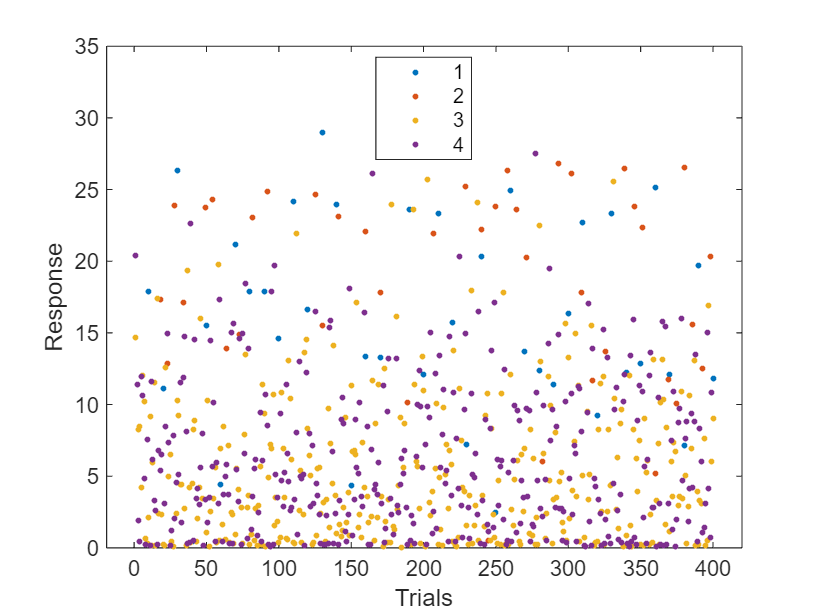

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           16.795       1.7692      9.4931    2.5679e-20
    Tiempo            -0.0035001    0.0075201    -0.46544       0.64175
    Grupo_2               3.6119       2.5267      1.4295       0.15326
    Grupo_3              -11.832       1.8614     -6.3569    3.4749e-10
    Grupo_4              -10.612       1.8615     -5.7011      1.68e-08
    Tiempo:Grupo_2    -0.0039061     0.010335    -0.37795       0.70557
    Tiempo:Grupo_3     0.0046418    0.0079341     0.58504       0.55868
    

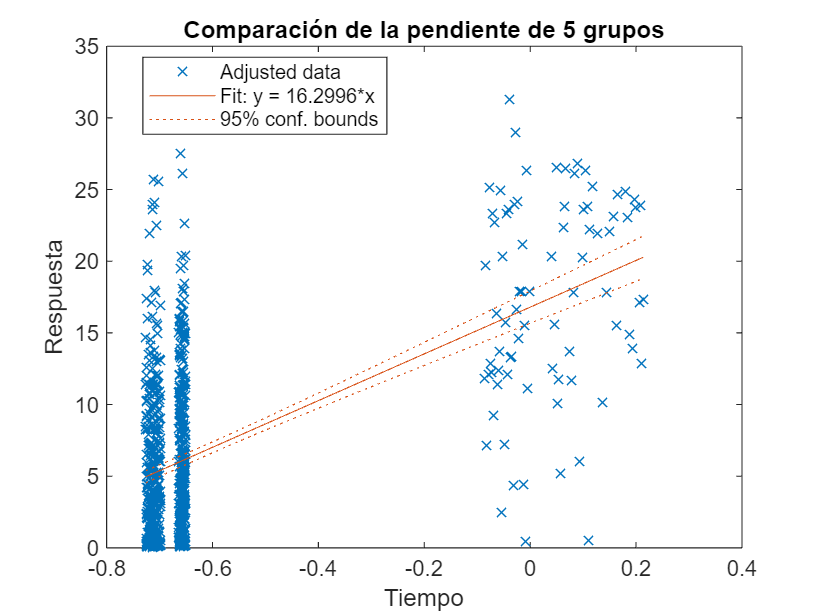

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD R vs P
% STD P referencia
Trials = [STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40)];
Response = [STDcount_P./n;STDcountRest_P./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n];
Group = [ ones(360,1)*4;ones(40,1); ones(360,1)*2; ones(40,1)*3];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

%% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           20.407       1.8039     11.313    1.3081e-27
    Tiempo            -0.0074063    0.0070895    -1.0447       0.29649
    Grupo_2              -15.444       1.8944    -8.1527    1.3878e-15
    Grupo_3              -3.6119       2.5267    -1.4295       0.15326
    Grupo_4              -14.224       1.8945    -7.5083    1.6155e-13
    Tiempo:Grupo_2     0.0085479    0.0075273     1.1356       0.25647
    Tiempo:Grupo_3     0.0039061     0.010335    0.37795       0.70557
    Tiempo:Gru


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq     DF     MeanSq       F         pValue  
                   ______    ___    ______    _______    __________

    Total           34200    799    42.804                         
    Model           10328      7    1475.4     48.947    7.1846e-58
    . Linear        10282      4    2570.5     85.278    3.0397e-60
    . Nonlinear    45.746      3    15.249    0.50589       0.67831
    Residual        23873    792    30.142                         


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        5.2324e-27               1.186      
        5.5514e-15              1.0259      
           0.61304              2.8223      
        6.4619e-13              1.4379      


%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           20.407       1.8039     11.313    1.3081e-27
    Tiempo            -0.0074063    0.0070895    -1.0447       0.29649
    Grupo_2              -15.444       1.8944    -8.1527    1.3878e-15
    Grupo_3              -3.6119       2.5267    -1.4295       0.15326
    Grupo_4              -14.224       1.8945    -7.5083    1.6155e-13
    Tiempo:Grupo_2     0.0085479    0.0075273     1.1356       0.25647
    Tiempo:Grupo_3     0.0039061     0.010335    0.37795       0.70557
    Tiemp

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

spike_counts_MSC = zeros(1,400);
for i = 1:40
spike_counts_MSC(1,CTRMSTrialsComplete_F1(1).CTRMStrials(i)) = MScount_F1(i,1)./n;
spike_counts_MSC(1,CTRMSTrialsComplete_F2(1).CTRMStrials(i)) = MScount_F2(i,1)./n;
end

for j = 1:320
spike_counts_MSC(1,MStrialsRest(1).MStrials(j)) = MScount_rest(j,1)./n;
end

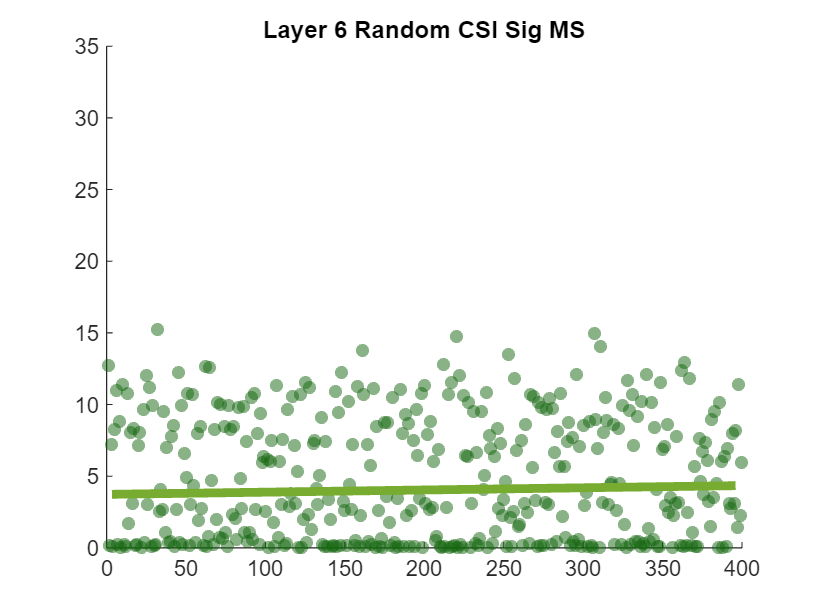

%MS
figure
scatter(CTRMSTrialsComplete_F1(1).CTRMStrials, MScount_F1./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('Layer 6 Random CSI Sig MS')
hold on
scatter(CTRMSTrialsComplete_F2(1).CTRMStrials, MScount_F2./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(MStrialsRest(1).MStrials, MScount_rest./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
ylim([0,35])

        p1 = polyfit(CTRMSTrialsComplete_F1(1).CTRMStrials,MScount_F1./n, 1);
        px1 = [min(CTRMSTrialsComplete_F1(1).CTRMStrials) max(CTRMSTrialsComplete_F1(1).CTRMStrials)];
        py = polyval(p1, px1);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

         p2 = polyfit(CTRMSTrialsComplete_F2(1).CTRMStrials,MScount_F2./n, 1);
        px2 = [min(CTRMSTrialsComplete_F2(1).CTRMStrials) max(CTRMSTrialsComplete_F2(1).CTRMStrials)];
        py = polyval(p2, px2);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

         pT = polyfit(MStrialsRest(1).MStrials,MScount_rest./n, 1);
        pxT = [min(MStrialsRest(1).MStrials) max(MStrialsRest(1).MStrials)];
        py = polyval(pT, pxT);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

        P= (p1+p2+pT)./3;
        Px = (px1+px2+pxT)./3;
        py = polyval(P, Px);
        plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

% x = 0:400;
% y_msc = 2.2546 + (0.0019218) * x;
% plot(x,y_msc, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])
% 
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer6_Sig_SpkPerTrial_MS.tif');
saveas(gcf,['Layer6_Sig_SpkPerTrial_MS.fig']);
saveas(gcf,['Layer6_Sig_SpkPerTrial_MS.pdf']);

spike_counts_CASCASC = zeros(1,400);
for i = 1:40
spike_counts_CASCASC(1,CTR_ASC_F1TrialsComplete(1).CTRtrials(i)) = CASCasccount_F1(i,1)./n;
spike_counts_CASCASC(1,CTR_ASC_F2TrialsComplete(1).CTRtrials(i)) = CASCasccount_F2(i,1)./n;
end

for j = 1:320
spike_counts_CASCASC(1,CASCasctrialsRest(1).CASCasctrials(j)) = CASCasccount_rest(j,1)./n;
end

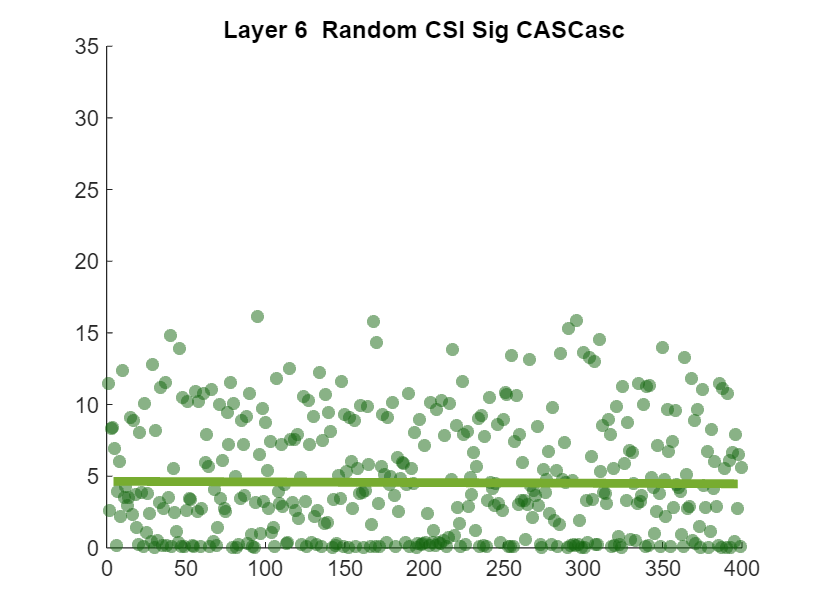

%CASCASC
figure
scatter(CTR_ASC_F1TrialsComplete(1).CTRtrials, CASCasccount_F1./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('Layer 6  Random CSI Sig CASCasc')
hold on
scatter(CTR_ASC_F2TrialsComplete(1).CTRtrials, CASCasccount_F2./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(CASCasctrialsRest(1).CASCasctrials, CASCasccount_rest./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
% cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CASCASC.tif');
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.fig']);
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.pdf']);
ylim([0,35])

        p1 = polyfit(CTR_ASC_F1TrialsComplete(1).CTRtrials,CASCasccount_F1./n, 1);
        px1 = [min(CTR_ASC_F1TrialsComplete(1).CTRtrials) max(CTR_ASC_F1TrialsComplete(1).CTRtrials)];
        py = polyval(p1, px1);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

         p2 = polyfit(CTR_ASC_F2TrialsComplete(1).CTRtrials,CASCasccount_F2./n, 1);
        px2 = [min(CTR_ASC_F2TrialsComplete(1).CTRtrials) max(CTR_ASC_F2TrialsComplete(1).CTRtrials)];
        py = polyval(p2, px2);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

         pT = polyfit(CASCasctrialsRest(1).CASCasctrials,CASCasccount_rest./n, 1);
        pxT = [min(CASCasctrialsRest(1).CASCasctrials) max(CASCasctrialsRest(1).CASCasctrials)];
        py = polyval(pT, pxT);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

        P= (p1+p2+pT)./3;
        Px = (px1+px2+pxT)./3;
        py = polyval(P, Px);
        plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

% x = 0:400;
% y_cascasc = 2.5347 + (-0.00094849) * x;
% plot(x,y_cascasc, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])
% 
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer6_Sig_SpkPerTrial_CASCasc.tif');
saveas(gcf,['Layer6_Sig_SpkPerTrial_CASCasc.fig']);
saveas(gcf,['Layer6_Sig_SpkPerTrial_CASCasc.pdf']);

spike_counts_CASCDES = zeros(1,400);
for i = 1:40
spike_counts_CASCDES(1,CTR_DESC_F1TrialsComplete(1).CTRtrials(i)) = CASCdescount_F1(i,1)./n;
spike_counts_CASCDES(1,CTR_DESC_F2TrialsComplete(1).CTRtrials(i)) = CASCdescount_F2(i,1)./n;
end

for j = 1:320
spike_counts_CASCDES(1,CASCdestrialsRest(1).CASCdes(j)) = CASCdescount_rest(j,1)./n;
end

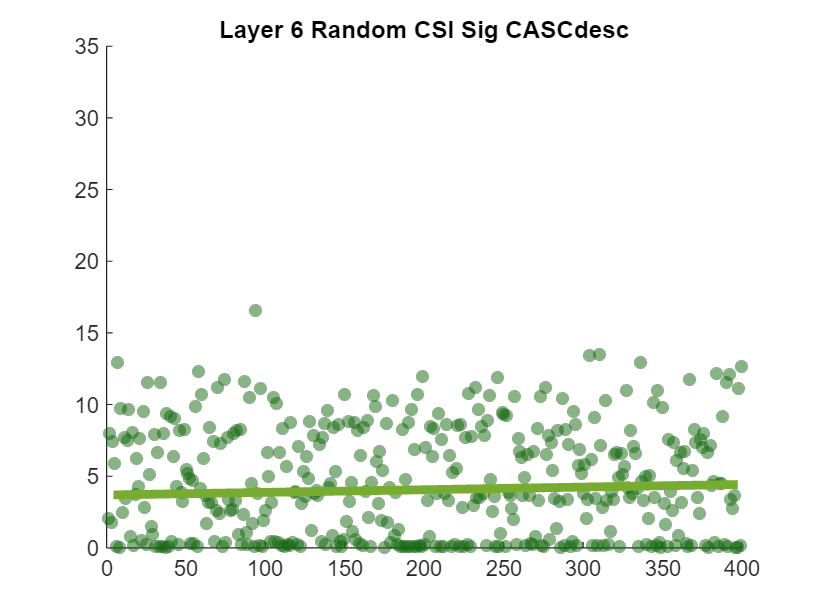

%CASCdesc
figure
scatter(CTR_DESC_F1TrialsComplete(1).CTRtrials, CASCdescount_F1./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
title ('Layer 6 Random CSI Sig CASCdesc')
hold on
scatter(CTR_DESC_F2TrialsComplete(1).CTRtrials, CASCdescount_F2./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
scatter(CASCdestrialsRest(1).CASCdes, CASCdescount_rest./n,'filled','MarkerFaceColor','#14660E','MarkerFaceAlpha',.5)
% cd ('C:\Jazmin\HIP\SpikePerCount')
% saveas(gcf,'HIP_Sig_Random_SpkPerTrial_CASCASC.tif');
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.fig']);
% saveas(gcf,['HIP_Sig_Random_SpkPerTrial_CASCASC.pdf']);
ylim([0,35])
        p1 = polyfit(CTR_DESC_F1TrialsComplete(1).CTRtrials,CASCdescount_F1./n, 1);
        px1 = [min(CTR_DESC_F1TrialsComplete(1).CTRtrials) max(CTR_DESC_F1TrialsComplete(1).CTRtrials)];
        py = polyval(p1, px1);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);

         p2 = polyfit(CTR_DESC_F2TrialsComplete(1).CTRtrials,CASCdescount_F2./n, 1);
        px2 = [min(CTR_DESC_F2TrialsComplete(1).CTRtrials) max(CTR_DESC_F2TrialsComplete(1).CTRtrials)];
        py = polyval(p2, px2);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

         pT = polyfit(CASCdestrialsRest(1).CASCdes,CASCdescount_rest./n, 1);
        pxT = [min(CASCdestrialsRest(1).CASCdes) max(CASCdestrialsRest(1).CASCdes)];
        py = polyval(pT, pxT);
        % plot(px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880],'linestyle','--');

        P= (p1+p2+pT)./3;
        Px = (px1+px2+pxT)./3;
        py = polyval(P, Px);
        plot(Px, py, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880]);
% 
% x = 0:400;
% y_cascdes = 2.6757 + (-0.0004692) * x;
% plot(x,y_cascdes, 'LineWidth', 4,'Color',[0.4660 0.6740 0.1880])
% 
cd ('D:\Jazmin\MultichannelDataTanks\Cortex\SpikePerCount')
saveas(gcf,'Layer6_Sig_SpkPerTrial_CASCdes.tif');
saveas(gcf,['Layer6_Sig_SpkPerTrial_CASCdes.fig']);
saveas(gcf,['Layer6_Sig_SpkPerTrial_CASCdes.pdf']);

% figure
% x = 0:400;
% y_dev = 5.3157 + (0.0033033) * x;
% plot(x,y_dev, 'LineWidth', 4,'Color',[1 0 0])
% ylim([0,16])
% hold on
% 
% y_std = 2.7570 + (0.0021288) * x;
% plot(x,y_std, 'LineWidth', 4,'Color',[0 0.4470 0.7410])
% 
% y_dev_p = 5.9515 + (0.0018401) * x;
% plot(x,y_dev_p, 'LineWidth', 4,'Color',[1 0 0],'linestyle','--')
% 
% y_std_p = 3.4611 + (0.00031385) * x;
% plot(x,y_std_p, 'LineWidth', 4,'Color',[0 0.4470 0.7410],'linestyle','--')
% 
% y_msc = 2.2546 + (0.0019218) * x;
% plot(x,y_msc, 'LineWidth', 4,'Color','#14733C')
% 
% y_cascasc = 2.5347 + (-0.00094849) * x;
% plot(x,y_cascasc, 'LineWidth', 4,'Color','#5CBA47')
% 
% y_cascdes = 2.6757 + (-0.0004692) * x;
% plot(x,y_cascdes, 'LineWidth', 4,'Color','#5CBA47','linestyle','--')
% 
% cd ('D:\Jazmin\MultichannelDataTanks\HIP\SpikePerCount')
% saveas(gcf,'HIP_Fits.tif');
% saveas(gcf,['HIP_Fits.fig']);
% saveas(gcf,['HIP_Fits.pdf']);

%ODD vs the rest
% DEV R; STD R; DEV P; STD P; MS; CASC ASC; CASC DESC
Trials = [ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(40,1); ones(360,1)*2; ones(40,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           20.407       1.5407     13.245    1.9484e-38
    Tiempo            -0.0074063    0.0060551    -1.2231       0.22142
    Grupo_2              -15.444        1.618    -9.5454    3.8213e-21
    Grupo_3              -3.6119       2.1581    -1.6737      0.094351
    Grupo_4              -14.224       1.6181    -8.7909    3.1463e-18
    Grupo_5              -15.597       1.6108    -9.6833    1.0626e-21
    Grupo_6              -15.617       1.6108    -9.6955    9.4795e-22
    Grupo_7   


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(9,1);
m_pvalues(3,1) = p_values(10,1);
m_pvalues(4,1) = p_values(11,1);
m_pvalues(5,1) = p_values(12,1);
m_pvalues(6,1) = p_values(13,1);
m_pvalues(7,1) = p_values(14,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);
y_pvalues(6,1) = p_values(7,1);
y_pvalues(7,1) = p_values(8,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F         pValue   
                   ______    ____    ______    _______    ___________

    Total           56075    1999    28.052                          
    Model           12407      13    954.36     43.403     3.9373e-98
    . Linear        12360       7    1765.7     80.304    7.0965e-103
    . Nonlinear    46.455       6    7.7425    0.35212        0.90895
    Residual        43669    1986    21.988                          


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
     3.9373e-98        1.9686e-97    
    7.0965e-103       3.5483e-102    
        0.90895            4.5447    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.3639e-37                1.55      
        2.6749e-20              1.2866      
           0.66046              4.6072      
        2.2024e-17              1.9821      
        7.4382e-21              1.7565      
        6.6357e-21              1.7266      
         2.273e-21              1.6894      


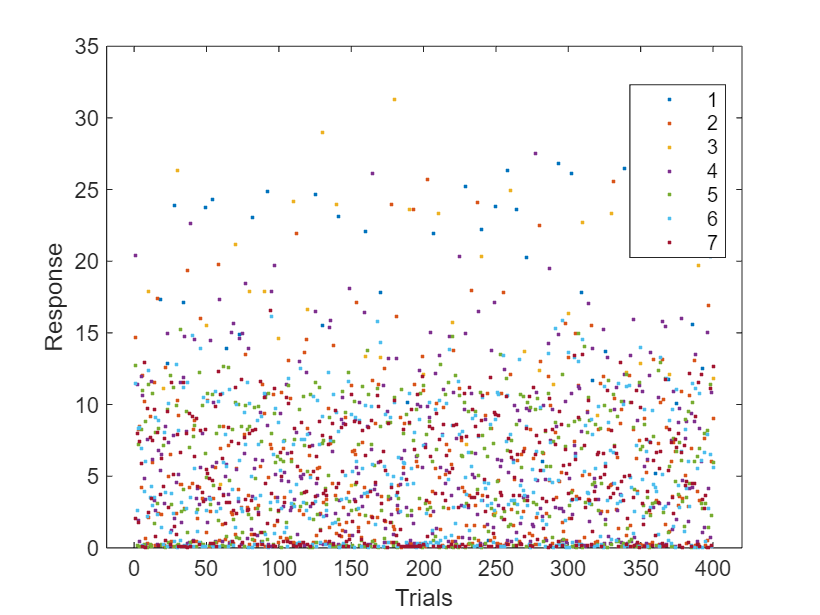

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat       pValue  
                      __________    _________    _______    __________

    (Intercept)           20.407       1.5407     13.245    1.9484e-38
    Tiempo            -0.0074063    0.0060551    -1.2231       0.22142
    Grupo_2              -15.444        1.618    -9.5454    3.8213e-21
    Grupo_3              -3.6119       2.1581    -1.6737      0.094351
    Grupo_4              -14.224       1.6181    -8.7909    3.1463e-18
    Grupo_5              -15.597       1.6108    -9.6833    1.0626e-21
    Grupo_6              -15.617       1.6108    -9.6955    9.4795e-22
    Grupo

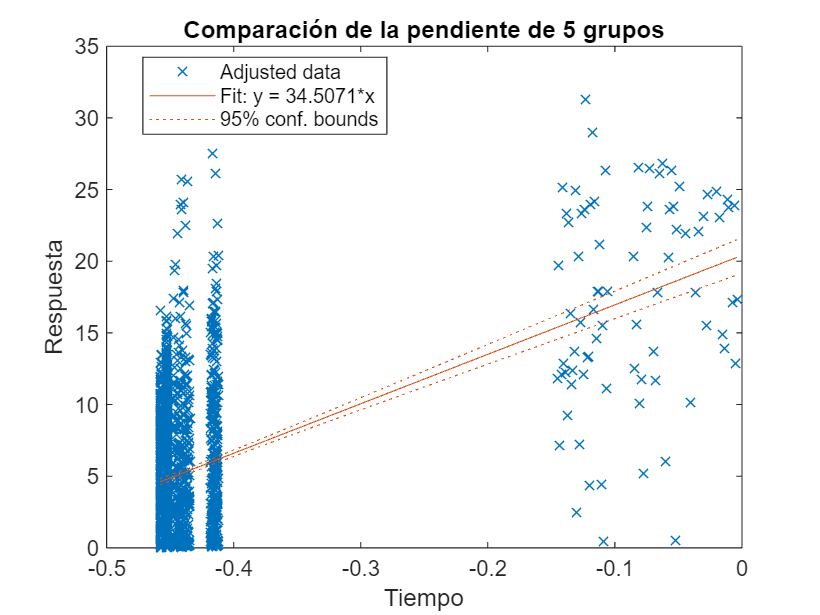

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD R vs the rest
% STD R; DEV R; DEV P; STD P; MS; CASC ASC; CASC DESC
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsComplete(1).ODDtrials(1:40);ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount./n;STDcountRest./n;DEVcount./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ ones(360,1)*1; ones(40,1)*2; ones(40,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           4.9629      0.49401      10.046     3.385e-23
    Tiempo             0.0011417    0.0021604     0.52845       0.59725
    Grupo_2               15.444        1.618      9.5454    3.8213e-21
    Grupo_3               11.832       1.5898      7.4428    1.4604e-13
    Grupo_4                 1.22      0.69885      1.7458      0.081006
    Grupo_5             -0.15305      0.68173     -0.2245       0.82239
    Grupo_6             -0.17272      0.68173    -0.25335       0.80002
    G


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F         pValue   
                   ______    ____    ______    _______    ___________

    Total           56075    1999    28.052                          
    Model           12407      13    954.36     43.403     3.9373e-98
    . Linear        12360       7    1765.7     80.304    7.0965e-103
    . Nonlinear    46.455       6    7.7425    0.35212        0.90895
    Residual        43669    1986    21.988                          


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
     3.9373e-98        1.9686e-97    
    7.0965e-103       3.5483e-102    
        0.90895            4.5447    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.3695e-22              4.1807      
        2.6749e-20              5.6001      
        1.0223e-12              4.2093      
           0.56704              1.2866      
            5.7567               3.454      
        6.6357e-21              1.7266      
         2.273e-21              1.6894      


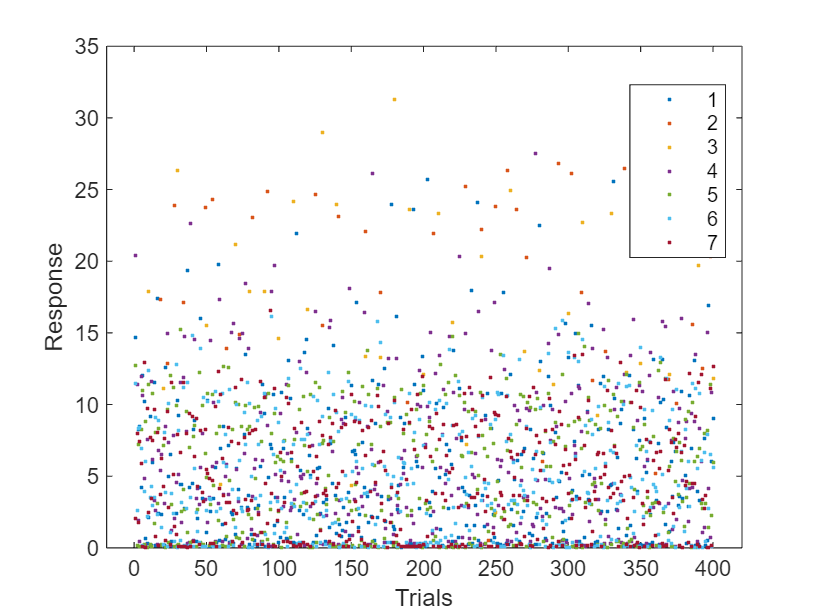

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           4.9629      0.49401      10.046     3.385e-23
    Tiempo             0.0011417    0.0021604     0.52845       0.59725
    Grupo_2               15.444        1.618      9.5454    3.8213e-21
    Grupo_3               11.832       1.5898      7.4428    1.4604e-13
    Grupo_4                 1.22      0.69885      1.7458      0.081006
    Grupo_5             -0.15305      0.68173     -0.2245       0.82239
    Grupo_6             -0.17272      0.68173    -0.25335       0.80002
    

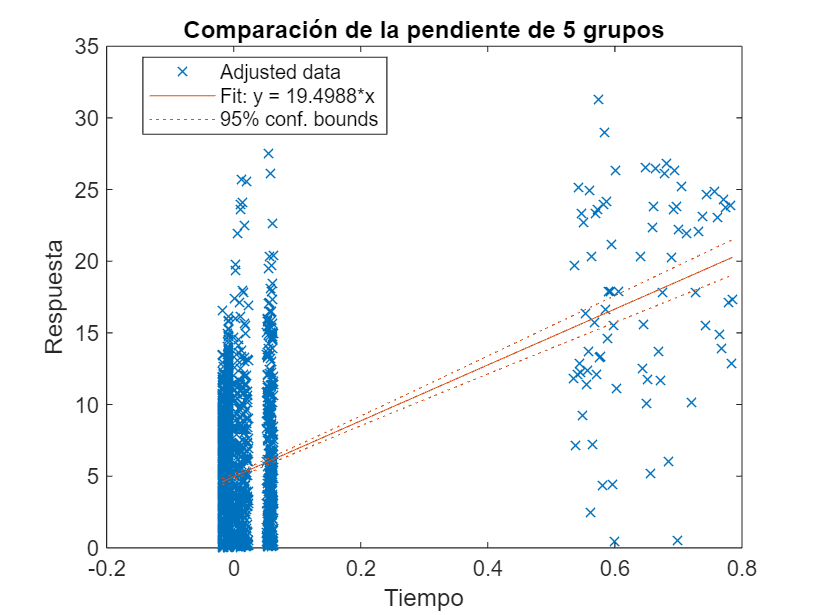

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%ODD P vs the rest
% DEV P; DEV R; STD R; STD P; MS; CASC ASC; CASC DESC
Trials = [ODDTrialsCompleteP(1).ODDtrialsP(1:40);ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [DEVcount_P./n;DEVcount./n;STDcount./n;STDcountRest./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(40,1)*1; ones(40,1)*2; ones(360,1)*3; ones(360,1)*4;ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           16.795       1.5111      11.115    6.9343e-28
    Tiempo            -0.0035001    0.0064229    -0.54495       0.58585
    Grupo_2               3.6119       2.1581      1.6737      0.094351
    Grupo_3              -11.832       1.5898     -7.4428    1.4604e-13
    Grupo_4              -10.612       1.5899      -6.675    3.1979e-11
    Grupo_5              -11.986       1.5824     -7.5741    5.5072e-14
    Grupo_6              -12.005       1.5824     -7.5865    5.0176e-14
    G


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F         pValue   
                   ______    ____    ______    _______    ___________

    Total           56075    1999    28.052                          
    Model           12407      13    954.36     43.403     3.9373e-98
    . Linear        12360       7    1765.7     80.304    7.0965e-103
    . Nonlinear    46.455       6    7.7425    0.35212        0.90895
    Residual        43669    1986    21.988                          


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
     3.9373e-98        1.9686e-97    
    7.0965e-103       3.5483e-102    
        0.90895            4.5447    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

         4.854e-27                 4.101    
           0.66046            3.5123e-13    
        1.0223e-12            1.4634e-13    
        2.2385e-10                4.6072    
        3.8551e-13                 3.454    
        6.6357e-21                1.7266    
         2.273e-21                1.6894    


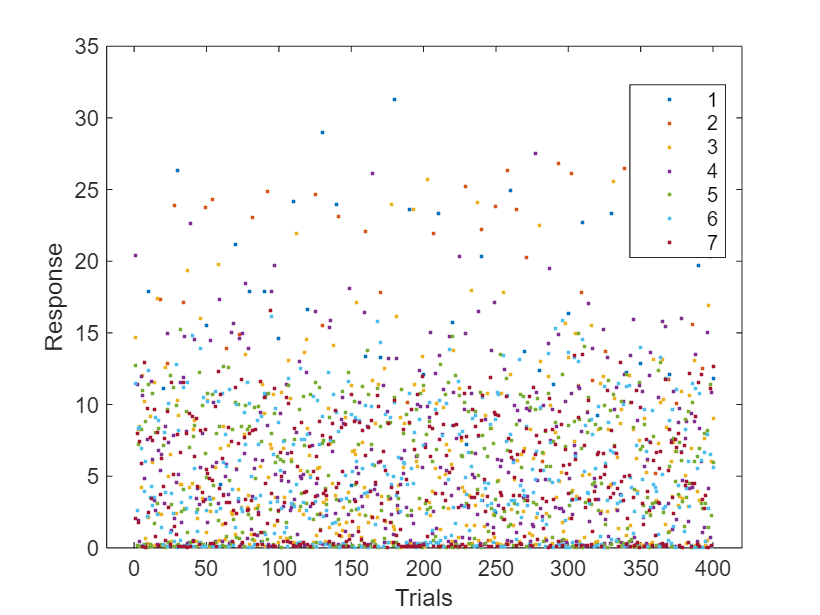

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           16.795       1.5111      11.115    6.9343e-28
    Tiempo            -0.0035001    0.0064229    -0.54495       0.58585
    Grupo_2               3.6119       2.1581      1.6737      0.094351
    Grupo_3              -11.832       1.5898     -7.4428    1.4604e-13
    Grupo_4              -10.612       1.5899      -6.675    3.1979e-11
    Grupo_5              -11.986       1.5824     -7.5741    5.5072e-14
    Grupo_6              -12.005       1.5824     -7.5865    5.0176e-14
    

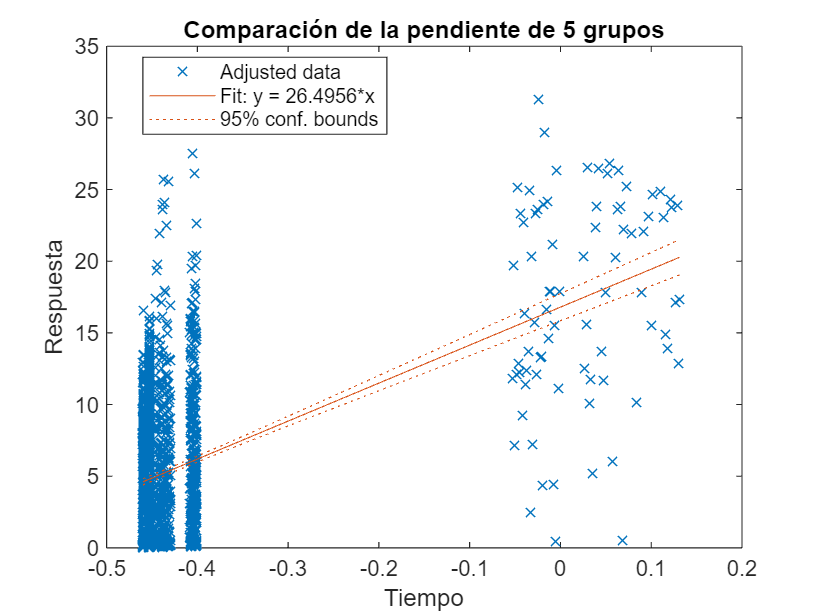

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD P vs the rest
% STD P; DEV R; STD R; DEV P; MS; CASC ASC; CASC DESC
Trials = [STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount_P./n;STDcountRest_P./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(360,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(400,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)             6.183       0.4943      12.508    1.3043e-34
    Tiempo            -0.00051155    0.0021404      -0.239       0.81113
    Grupo_2                14.224       1.6181      8.7909    3.1463e-18
    Grupo_3                 -1.22      0.69885     -1.7458      0.081006
    Grupo_4                10.612       1.5899       6.675    3.1979e-11
    Grupo_5               -1.3731      0.68194     -2.0135        0.0442
    Grupo_6               -1.3927      0.68194     -2.0423      0.041252
    


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F         pValue   
                   ______    ____    ______    _______    ___________

    Total           56075    1999    28.052                          
    Model           12407      13    954.36     43.403     3.9373e-98
    . Linear        12360       7    1765.7     80.304    7.0965e-103
    . Nonlinear    46.455       6    7.7425    0.35212        0.90895
    Residual        43669    1986    21.988                          


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
     3.9373e-98        1.9686e-97    
    7.0965e-103       3.5483e-102    
        0.90895            4.5447    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        9.1304e-34              5.6779      
        2.2024e-17             0.28876      
           0.56704             0.14637      
        2.2385e-10              1.9821      
            0.3094              4.1074      
        6.6357e-21              1.7266      
         2.273e-21              1.6894      


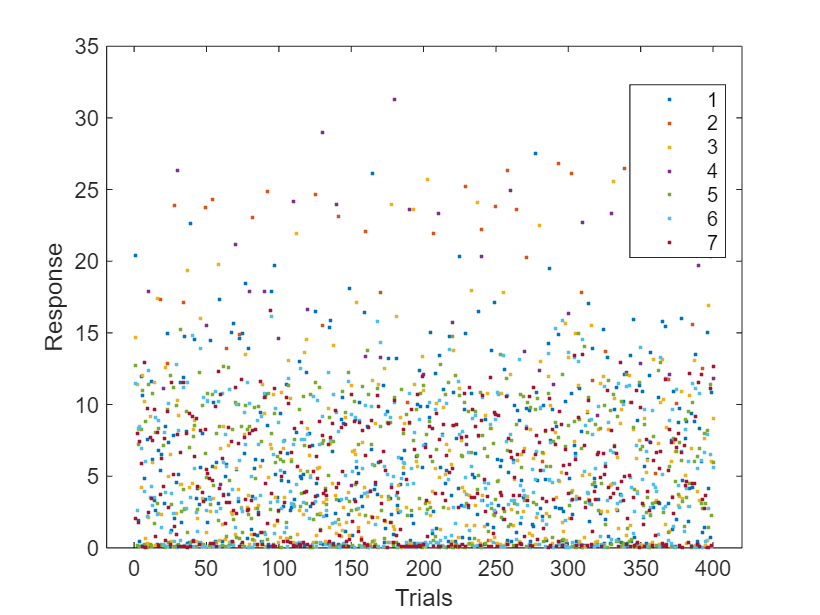

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE         tStat        pValue  
                      ___________    _________    ________    __________

    (Intercept)             6.183       0.4943      12.508    1.3043e-34
    Tiempo            -0.00051155    0.0021404      -0.239       0.81113
    Grupo_2                14.224       1.6181      8.7909    3.1463e-18
    Grupo_3                 -1.22      0.69885     -1.7458      0.081006
    Grupo_4                10.612       1.5899       6.675    3.1979e-11
    Grupo_5               -1.3731      0.68194     -2.0135        0.0442
    Grupo_6               -1.3927      0.68194     -2.0423      0.041252

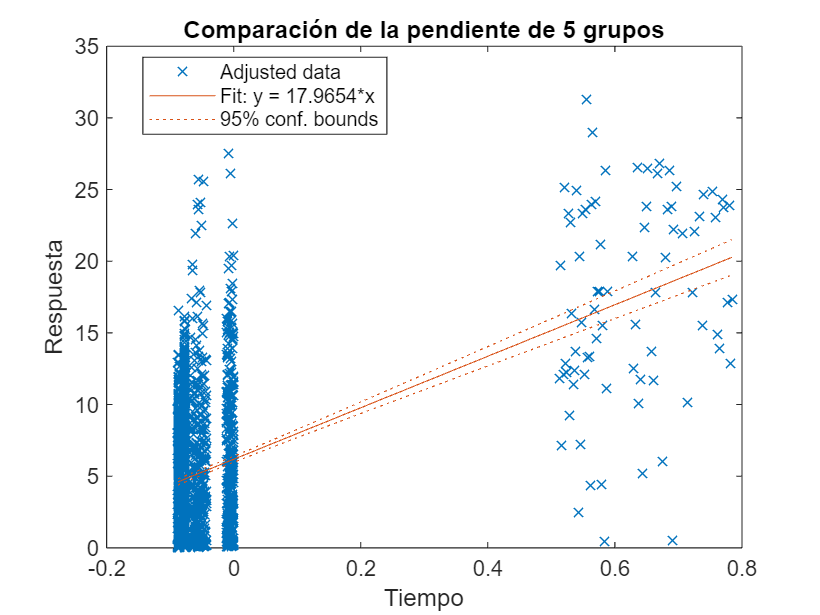

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%MS vs the rest
% MS; DEV R; STD R; DEV P; STD P; CASC ASC; CASC DESC
Trials = [CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [MScount_F1./n;MScount_F2./n; MScount_rest./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(400,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            4.8099       0.4698       10.238    5.2172e-24
    Tiempo            -7.1795e-05    0.0020305    -0.035359        0.9718
    Grupo_2                15.597       1.6108       9.6833    1.0626e-21
    Grupo_3               0.15305      0.68173       0.2245       0.82239
    Grupo_4                11.986       1.5824       7.5741    5.5072e-14
    Grupo_5                1.3731      0.68194       2.0135        0.0442
    Grupo_6             -0.019671      0.66439    -0.029607       0.9


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F         pValue   
                   ______    ____    ______    _______    ___________

    Total           56075    1999    28.052                          
    Model           12407      13    954.36     43.403     3.9373e-98
    . Linear        12360       7    1765.7     80.304    7.0965e-103
    . Nonlinear    46.455       6    7.7425    0.35212        0.90895
    Residual        43669    1986    21.988                          


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
     3.9373e-98        1.9686e-97    
    7.0965e-103       3.5483e-102    
        0.90895            4.5447    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        3.6521e-23              6.8026      
        7.4382e-21              6.8347      
            5.7567              5.3183      
        3.8551e-13              1.7565      
            0.3094              4.7766      
        6.6357e-21              1.7266      
         2.273e-21              1.6894      


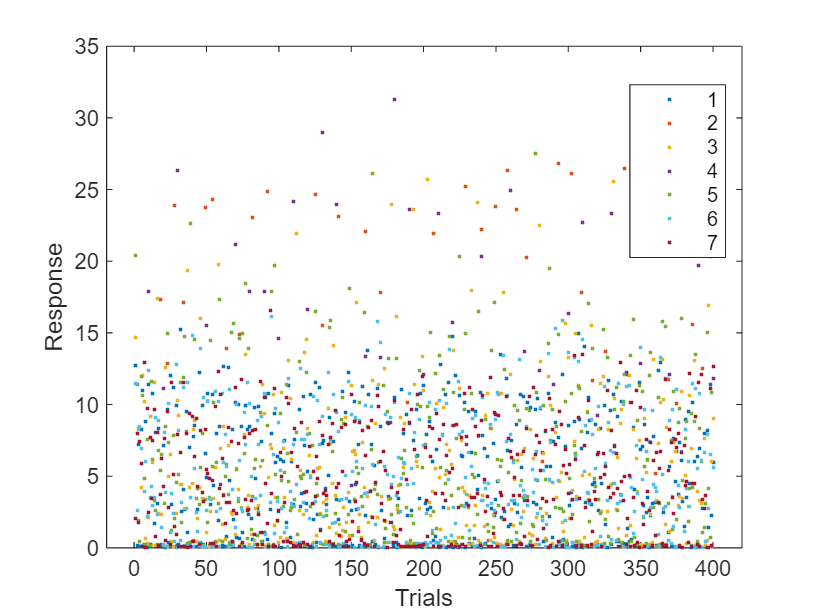

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            4.8099       0.4698       10.238    5.2172e-24
    Tiempo            -7.1795e-05    0.0020305    -0.035359        0.9718
    Grupo_2                15.597       1.6108       9.6833    1.0626e-21
    Grupo_3               0.15305      0.68173       0.2245       0.82239
    Grupo_4                11.986       1.5824       7.5741    5.5072e-14
    Grupo_5                1.3731      0.68194       2.0135        0.0442
    Grupo_6             -0.019671      0.66439    -0.029607     

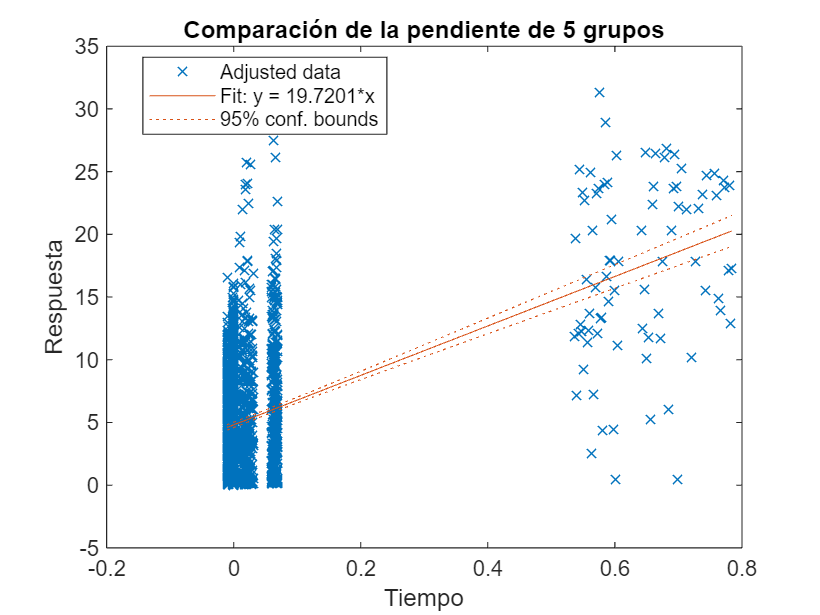

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%CASC ASC vs the rest
% CASC ASC; DEV R; STD R; DEV P; STD P; MS; CASC DESC
Trials = [CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(400,1)*1;ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat         pValue  
                      ___________    _________    __________    __________

    (Intercept)            4.7902       0.4698        10.196    7.8635e-24
    Tiempo             -5.164e-06    0.0020305    -0.0025432       0.99797
    Grupo_2                15.617       1.6108        9.6955    9.4795e-22
    Grupo_3               0.17272      0.68173       0.25335       0.80002
    Grupo_4                12.005       1.5824        7.5865    5.0176e-14
    Grupo_5                1.3927      0.68194        2.0423      0.041252
    Grupo_6              0.019671      0.66439      0.029607 


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F         pValue   
                   ______    ____    ______    _______    ___________

    Total           56075    1999    28.052                          
    Model           12407      13    954.36     43.403     3.9373e-98
    . Linear        12360       7    1765.7     80.304    7.0965e-103
    . Nonlinear    46.455       6    7.7425    0.35212        0.90895
    Residual        43669    1986    21.988                          


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
     3.9373e-98        1.9686e-97    
    7.0965e-103       3.5483e-102    
        0.90895            4.5447    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        5.5044e-23              6.9858      
        6.6357e-21              6.8347      
            5.6001              5.4767      
        3.5123e-13              1.7266      
           0.28876              4.8926      
        6.6357e-21              1.7266      
         2.273e-21              1.6894      


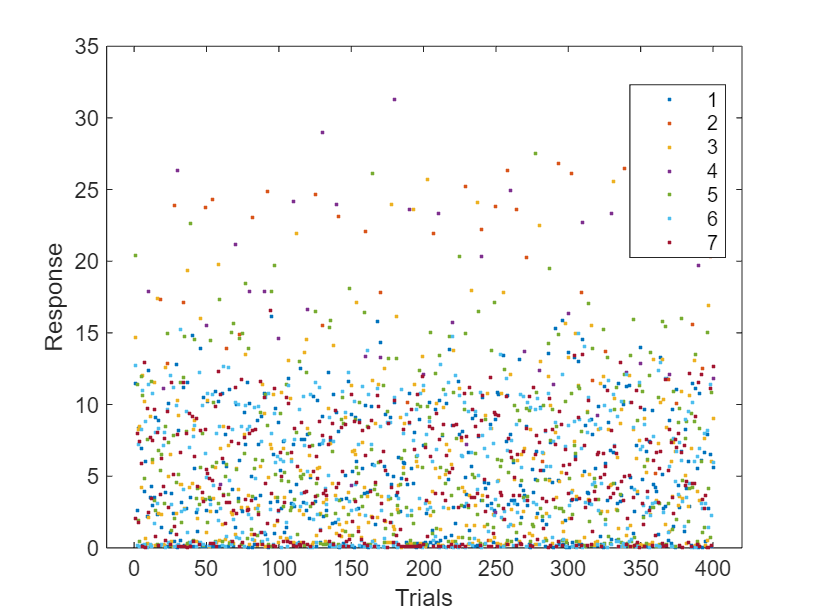

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat         pValue  
                      ___________    _________    __________    __________

    (Intercept)            4.7902       0.4698        10.196    7.8635e-24
    Tiempo             -5.164e-06    0.0020305    -0.0025432       0.99797
    Grupo_2                15.617       1.6108        9.6955    9.4795e-22
    Grupo_3               0.17272      0.68173       0.25335       0.80002
    Grupo_4                12.005       1.5824        7.5865    5.0176e-14
    Grupo_5                1.3927      0.68194        2.0423      0.041252
    Grupo_6              0.019671      0.66439      0.02

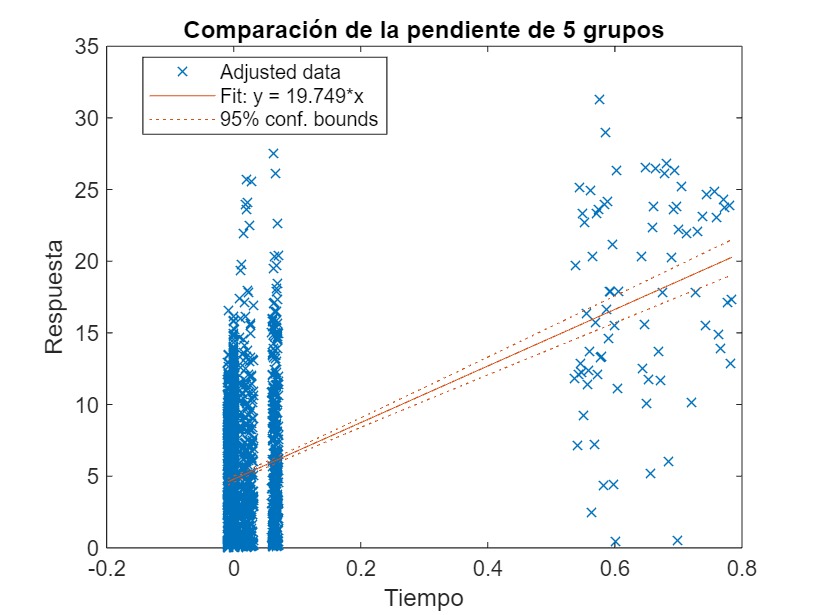

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%CASC DESC vs the rest
% CASC DESC; DEV R; STD R; DEV P; STD P; MS; CASC ASC
Trials = [CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes;ODDTrialsComplete(1).ODDtrials(1:40);STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;ODDTrialsCompleteP(1).ODDtrialsP(1:40);STDTrialsComplete_P(1).STDtrials(1:40);AllSTDtrialsRest_P(1).STDtrialsP;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials];
    Response = [CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n;DEVcount./n;STDcount./n;STDcountRest./n;DEVcount_P./n;STDcount_P./n;STDcountRest_P./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n];
Group = [ones(400,1)*1; ones(40,1)*2; ones(360,1)*3; ones(40,1)*4; ones(360,1)*5; ones(400,1)*6; ones(400,1)*7];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            4.6067       0.4698       9.8057    3.3641e-22
    Tiempo             7.8683e-05    0.0020305     0.038751       0.96909
    Grupo_2                15.801       1.6108       9.8094    3.2472e-22
    Grupo_3               0.35625      0.68173      0.52257       0.60133
    Grupo_4                12.189       1.5824       7.7025    2.0905e-14
    Grupo_5                1.5763      0.68194       2.3114       0.02091
    Grupo_6                0.2032      0.66439      0.30585       0.7


% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(7,1);
m_pvalues(3,1) = p_values(8,1);
m_pvalues(4,1) = p_values(9,1);
m_pvalues(5,1) = p_values(10,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);
y_pvalues(5,1) = p_values(6,1);

m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F         pValue   
                   ______    ____    ______    _______    ___________

    Total           56075    1999    28.052                          
    Model           12407      13    954.36     43.403     3.9373e-98
    . Linear        12360       7    1765.7     80.304    7.0965e-103
    . Nonlinear    46.455       6    7.7425    0.35212        0.90895
    Residual        43669    1986    21.988                          


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

table(pValues, correctedPValues, 'VariableNames', {'old pValue', 'm Bonfe_Cor_pValue'})

ans = 5×2 table
    old pValue     m Bonfe_Cor_pValue
    ___________    __________________

                              NaN    
     3.9373e-98        1.9686e-97    
    7.0965e-103       3.5483e-102    
        0.90895            4.5447    
                              NaN    


% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 7×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.3549e-21              6.7836      
         2.273e-21              5.3183      
            4.2093              5.4767      
        1.4634e-13              1.6894      
           0.14637              5.0399      
        6.6357e-21              1.7266      
         2.273e-21              1.6894      


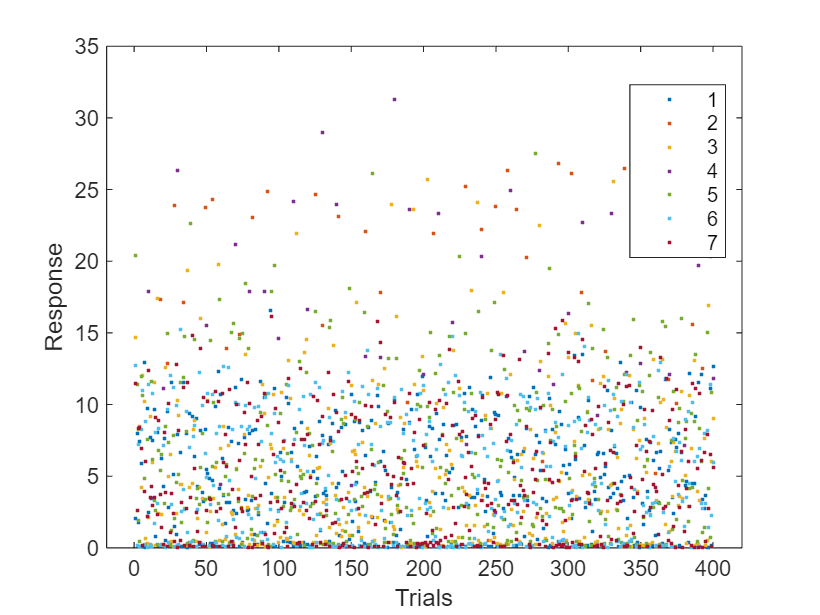

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

figure
lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo

lm = Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            4.6067       0.4698       9.8057    3.3641e-22
    Tiempo             7.8683e-05    0.0020305     0.038751       0.96909
    Grupo_2                15.801       1.6108       9.8094    3.2472e-22
    Grupo_3               0.35625      0.68173      0.52257       0.60133
    Grupo_4                12.189       1.5824       7.7025    2.0905e-14
    Grupo_5                1.5763      0.68194       2.3114       0.02091
    Grupo_6                0.2032      0.66439      0.30585     

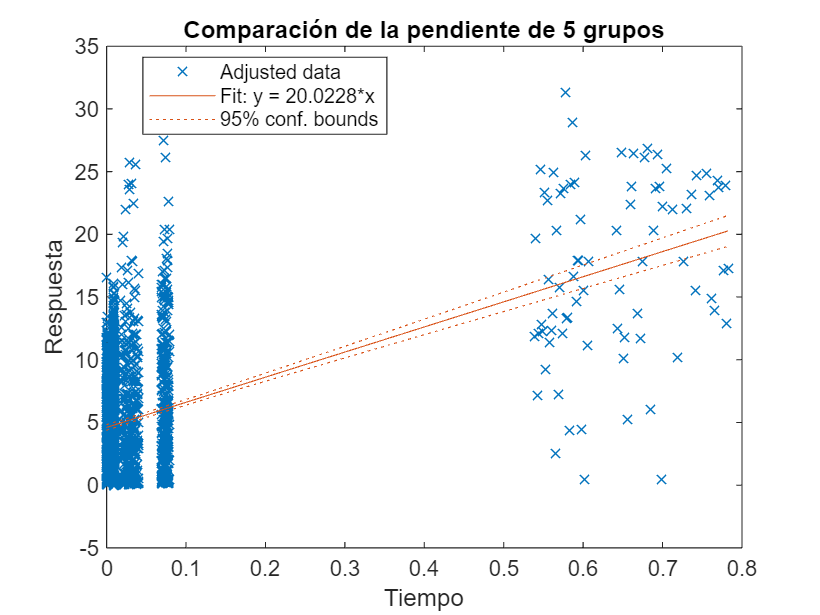

plot(lm) % Muestra las líneas de tendencia ajustadas
hold off;
title('Comparación de la pendiente de 5 grupos');
xlabel('Tiempo');
ylabel('Respuesta');

%STD vs CTR
Trials = [STDTrialsComplete(1).STDtrials(1:40);AllSTDtrialsRest(1).STDtrials;CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [STDcount./n;STDcountRest./n;MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(360,1)*2; ones(400,1)*3; ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE         tStat        pValue  
                      __________    _________    ________    __________

    (Intercept)           4.9629      0.45986      10.792    3.1123e-26
    Tiempo             0.0011417    0.0020111      0.5677       0.57032
    Grupo_3             -0.15305       0.6346    -0.24117       0.80945
    Grupo_4             -0.17272       0.6346    -0.27217       0.78553
    Grupo_5             -0.35625       0.6346    -0.56138       0.57462
    Tiempo:Grupo_3    -0.0012135    0.0027599    -0.43968       0.66023
    Tiempo:Grupo_4    -0.0011468    0.0027599    -0.41554        0.6778
    T


clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(6,1);
m_pvalues(3,1) = p_values(7,1);
m_pvalues(4,1) = p_values(8,1);


y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);
y_pvalues(4,1) = p_values(5,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                   SumSq      DF     MeanSq       F        pValue 
                   ______    ____    ______    ________    _______

    Total           29641    1559    19.013                       
    Model          70.799       7    10.114     0.53085    0.81169
    . Linear           66       4      16.5       0.866    0.48362
    . Nonlinear    4.7995       3    1.5998    0.083968    0.96879
    Residual        29570    1552    19.053                       


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 4×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        1.2449e-25              2.2813      
            3.2378              2.6409      
            3.1421              2.7112      
            2.2985              2.8007      


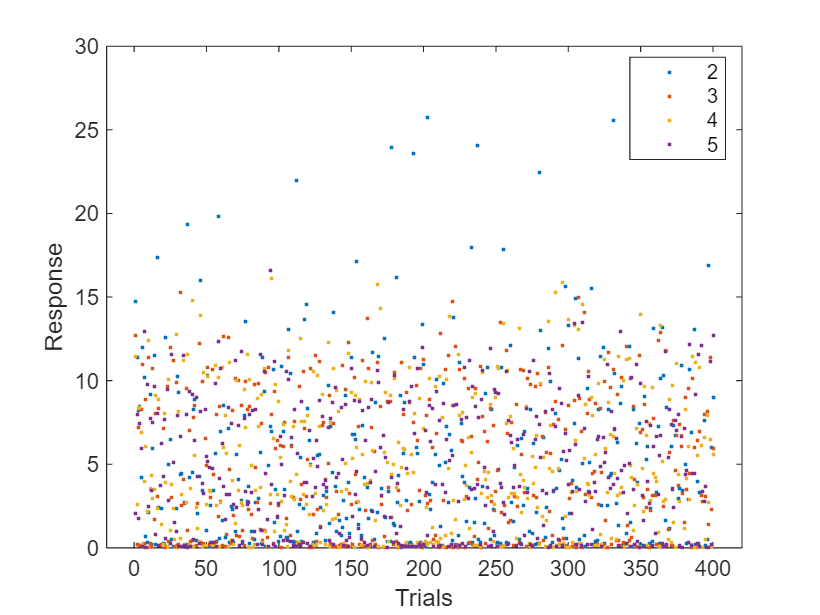

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

%CTR MS vs CASC
Trials = [CTRMSTrialsComplete_F1(1).CTRMStrials;CTRMSTrialsComplete_F2(1).CTRMStrials;MStrialsRest(1).MStrials;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [MScount_F1./n;MScount_F2./n; MScount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(400,1)*3; ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate         SE          tStat        pValue  
                      ___________    _________    _________    __________

    (Intercept)            4.8099      0.40794       11.791    1.9762e-30
    Tiempo            -7.1795e-05    0.0017631     -0.04072       0.96753
    Grupo_4             -0.019671      0.57692    -0.034096       0.97281
    Grupo_5               -0.2032      0.57692     -0.35222       0.72473
    Tiempo:Grupo_4     6.6631e-05    0.0024935     0.026722       0.97869
    Tiempo:Grupo_5     0.00015048    0.0024935     0.060349       0.95189


Number of observations: 1200, Error degrees of freedom: 1194
Root Mean Squared Error



clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(5,1);
m_pvalues(3,1) = p_values(6,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);
y_pvalues(3,1) = p_values(4,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                    SumSq       DF      MeanSq         F        pValue 
                   ________    ____    ________    _________    _______

    Total             19804    1199      16.517                        
    Model            7.7641       5      1.5528     0.093659    0.99322
    . Linear         7.7035       3      2.5678      0.15488    0.92657
    . Nonlinear    0.060646       2    0.030323    0.0018289    0.99817
    Residual          19796    1194       16.58                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 3×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        5.9286e-30              2.9026      
            2.9184              2.9361      
            2.1742              2.8557      


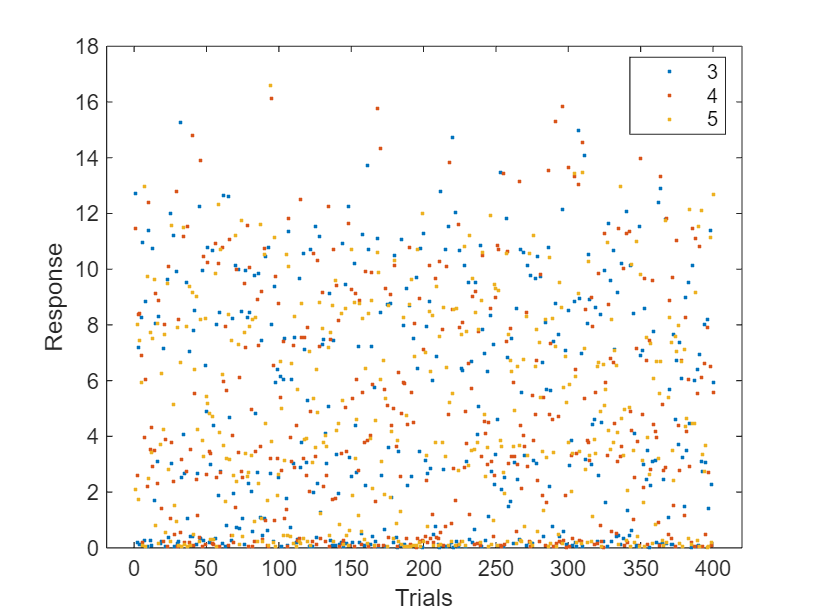

%%%%%%%%%%%%%%%%%%%%%%%
figure;
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

% ASC vs DESC
Trials = [CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials;CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes];
Response = [CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n;CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n];
Group = [ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
modelo = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo');

% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE          tStat         pValue  
                      __________    _________    __________    __________

    (Intercept)           4.7902      0.39911        12.002    1.2717e-30
    Tiempo            -5.164e-06     0.001725    -0.0029937       0.99761
    Grupo_5             -0.18353      0.56443      -0.32517       0.74514
    Tiempo:Grupo_5    8.3847e-05    0.0024395      0.034371       0.97259


Number of observations: 800, Error degrees of freedom: 796
Root Mean Squared Error: 3.98
R-squared: 0.000443,  Adjusted R-Squared: -0.00332
F-statistic vs. constant model: 0.117, p-value = 0.95



% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m = length(p_values); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = p_values * m; 
% Display results
clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(4,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                    SumSq      DF      MeanSq         F        pValue 
                   ________    ___    ________    _________    _______

    Total             12638    799      15.817                        
    Model            5.5924      3      1.8641      0.11747    0.94986
    . Linear         5.5736      2      2.7868      0.17561    0.83898
    . Nonlinear    0.018747      1    0.018747    0.0011814    0.97259
    Residual          12632    796      15.869                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 2×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.5433e-30              1.9952      
            1.4903              1.9452      


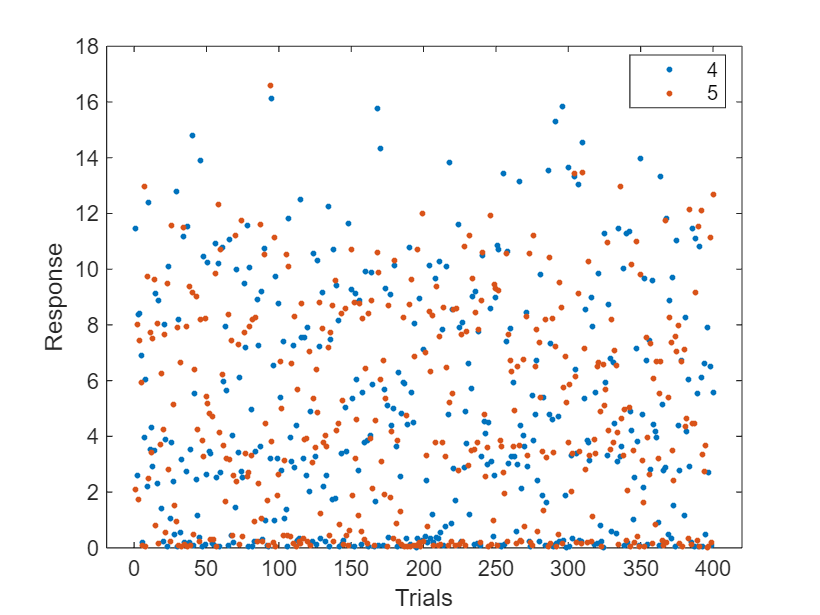

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

% DESC vs ASC 
Trials = [CTR_DESC_F1TrialsComplete(1).CTRtrials;CTR_DESC_F2TrialsComplete(1).CTRtrials;CASCdestrialsRest(1).CASCdes;CTR_ASC_F1TrialsComplete(1).CTRtrials;CTR_ASC_F2TrialsComplete(1).CTRtrials;CASCasctrialsRest(1).CASCasctrials];
Response = [CASCdescount_F1./n;CASCdescount_F2./n;CASCdescount_rest./n;CASCasccount_F1./n;CASCasccount_F2./n;CASCasccount_rest./n];
Group = [ones(400,1)*4; ones(400,1)*5];

tbl = table(Trials, categorical(Group), Response, 'VariableNames', {'Tiempo', 'Grupo', 'Respuesta'});

% Ajustar modelo ANCOVA con interacción
% Mostrar resultados
disp(modelo)

Linear regression model:
    Respuesta ~ 1 + Tiempo*Grupo

Estimated Coefficients:
                       Estimate        SE          tStat         pValue  
                      __________    _________    __________    __________

    (Intercept)           4.7902      0.39911        12.002    1.2717e-30
    Tiempo            -5.164e-06     0.001725    -0.0029937       0.99761
    Grupo_5             -0.18353      0.56443      -0.32517       0.74514
    Tiempo:Grupo_5    8.3847e-05    0.0024395      0.034371       0.97259


Number of observations: 800, Error degrees of freedom: 796
Root Mean Squared Error: 3.98
R-squared: 0.000443,  Adjusted R-Squared: -0.00332
F-statistic vs. constant model: 0.117, p-value = 0.95



% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m = length(p_values); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = p_values * m; 
% Display results
clear m_pvalues 
clear y_pvalues
% Extract p-values from the coefficients table
p_values = modelo.Coefficients.pValue;
m_pvalues(1,1) = p_values(2,1);
m_pvalues(2,1) = p_values(4,1);

y_pvalues(1,1) = p_values(1,1);
y_pvalues(2,1) = p_values(3,1);


m = length(y_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
y_correctedPValues = y_pvalues * m; 

m = length(m_pvalues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
m_correctedPValues = m_pvalues * m;

anovaResults = anova(modelo, 'summary') % Store results

anovaResults = 5×5 table
                    SumSq      DF      MeanSq         F        pValue 
                   ________    ___    ________    _________    _______

    Total             12638    799      15.817                        
    Model            5.5924      3      1.8641      0.11747    0.94986
    . Linear         5.5736      2      2.7868      0.17561    0.83898
    . Nonlinear    0.018747      1    0.018747    0.0011814    0.97259
    Residual          12632    796      15.869                        


pValues = anovaResults.pValue; % Extract p-values

m = length(pValues); % Number of tests
alpha = 0.05; % Standard significance level
correctedAlpha = alpha / m; % Adjusted significance threshold
correctedPValues = pValues * m;

% Display results
table(y_correctedPValues, m_correctedPValues, 'VariableNames', {'Y Bonfe_Cor_pValue', 'm Bonfe_Cor_pValue'})

ans = 2×2 table
    Y Bonfe_Cor_pValue    m Bonfe_Cor_pValue
    __________________    __________________

        2.5433e-30              1.9952      
            1.4903              1.9452      


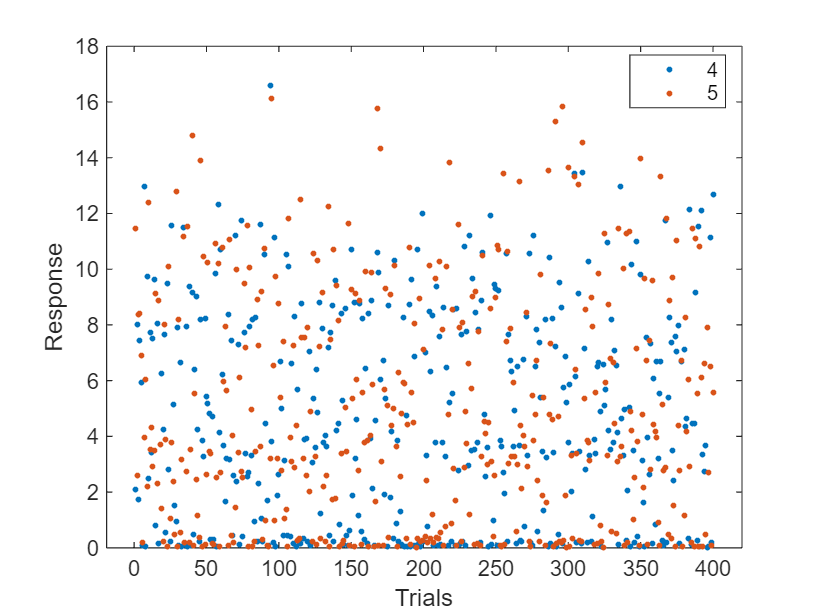

%%%%%%%%%%%%%%%%%%%%%%%
figure;
gscatter(Trials, Response, Group); % Gráfica de dispersión por grupo

% figure
% lm = fitlm(tbl, 'Respuesta ~ Tiempo * Grupo') % Ajuste del modelo
% plot(lm) % Muestra las líneas de tendencia ajustadas
% hold off;
% title('Comparación de la pendiente de 5 grupos');
% xlabel('Tiempo');
% ylabel('Respuesta');

MScount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,13));
        for i = 1:size(MStimes_F1{1,1},1)
            if MStimes_F1{1,1}(i) >= 200 && MStimes_F1{1,1}(i) <= 800
                MScount_F1V(k,j) = MScount_F1V(k,j) + 1;
            end
        end
    end
end

MScount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        MStimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,12));
        for i = 1:size(MStimes_F2{1,1},1)
            if MStimes_F2{1,1}(i) >= 200 && MStimes_F2{1,1}(i) <= 800
                MScount_F2V(k,j) = MScount_F2V(k,j) + 1;
            end
        end
    end
end

MScount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        MStimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,11));
        for i = 1:size(MStimesRest{1,1},1)
            if MStimesRest{1,1}(i) >= 200 && MStimesRest{1,1}(i) <= 800
                MScount_restV(k,j) = MScount_restV(k,j) + 1;
            end
        end
    end
end

CASCasccount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,15));
        for i = 1:size(CASCasctimes_F1{1,1},1)
            if CASCasctimes_F1{1,1}(i) >= 200 && CASCasctimes_F1{1,1}(i) <= 800
                CASCasccount_F1V(k,j) = CASCasccount_F1V(k,j) + 1;
            end
        end
    end
end

CASCasccount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCasctimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,16));
        for i = 1:size(CASCasctimes_F2{1,1},1)
            if CASCasctimes_F2{1,1}(i) >= 200 && CASCasctimes_F2{1,1}(i) <= 800
                CASCasccount_F2V(k,j) = CASCasccount_F2V(k,j) + 1;
            end
        end
    end
end

CASCasccount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCasctimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,14));
        for i = 1:size(CASCasctimesRest{1,1},1)
            if CASCasctimesRest{1,1}(i) >= 200 && CASCasctimesRest{1,1}(i) <= 800
                CASCasccount_restV(k,j) = CASCasccount_restV(k,j) + 1;
            end
        end
    end
end

CASCdescount_F1V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F1 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,19));
        for i = 1:size(CASCdestimes_F1{1,1},1)
            if CASCdestimes_F1{1,1}(i) >= 200 && CASCdestimes_F1{1,1}(i) <= 800
                CASCdescount_F1V(k,j) = CASCdescount_F1V(k,j) + 1;
            end
        end
    end
end

CASCdescount_F2V = zeros(40,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:40
        CASCdestimes_F2 = table2array(AllSpikeTable_Significance.spikes{j,1}(k,18));
        for i = 1:size(CASCdestimes_F2{1,1},1)
            if CASCdestimes_F2{1,1}(i) >= 200 && CASCdestimes_F2{1,1}(i) <= 800
                CASCdescount_F2V(k,j) = CASCdescount_F2V(k,j) + 1;
            end
        end
    end
end

CASCdescount_restV = zeros(320,size(AllSpikeTable_Significance,1));
for j = 1:size(AllSpikeTable_Significance,1)
    for k = 1:1:320
        CASCdestimesRest = table2array(AllSpikeTable_Significance.spikes{j,1}(k,17));
        for i = 1:size(CASCdestimesRest{1,1},1)
            if CASCdestimesRest{1,1}(i) >= 200 && CASCdestimesRest{1,1}(i) <= 800
                CASCdescount_restV(k,j) = CASCdescount_restV(k,j) + 1;
            end
        end
    end
end

sequence = zeros(1,400);
% ODDTrialIndex = ODDTrialIndex-20;
for i = 1:40
    for j = 1:400
        if ismember(j,ODDTrialIndex(i,1))
            sequence(1,j) = 1;
        end
    end
end


sequence_P = zeros(1,400);
% ODDTrialIndexP = ODDTrialIndexP-440;
for i = 1:40
    for j = 1:400
        if ismember(j,ODDTrialIndexP(i,1))
            sequence_P(1,j) = 1;
        end
    end
end


n = size(AllSpikeTable_Significance,1);

    DEVx = ODDTrialsComplete(1).ODDtrials(1:40);
    DEVy = DEVcount./n;

    STDTrialsComplete(1).STDtrials(1:40);
    STDx = STDcount./n;

    AllSTDtrialsRest(1).STDtrials;
    STD_Rest_y = STDcountRest./n;

    ODDTrialsCompleteP(1).ODDtrialsP(1:40);
    DEV_Px = DEVcount_P./n;

    STD_Py = STDTrialsComplete_P(1).STDtrials(1:40);
    STD_Px = STDcount_P./n;

    STD_Rest_Py = AllSTDtrialsRest_P(1).STDtrialsP;
    
    STD_Rest_Px = STDcountRest_P./n;

    MSC_F1y = CTRMSTrialsComplete_F1(1).CTRMStrials;
    MSC_F1x = MScount_F1./n;

    MSC_F2y = CTRMSTrialsComplete_F2(1).CTRMStrials;
    MSC_F2x = MScount_F2./n;

    MSC_Rest_y = MStrialsRest(1).MStrials;
    MSC_Rest_x = MScount_rest./n;

    CASC_ASC_F1y = CTR_ASC_F1TrialsComplete(1).CTRtrials;
    CASC_ASC_F1x = CASCasccount_F1./n;

    CASC_ASC_F2y = CTR_ASC_F2TrialsComplete(1).CTRtrials;
    CASC_ASC_F2x = CASCasccount_F2./n;

    CASC_ASC_Rest_y = CASCasctrialsRest(1).CASCasctrials;
    CASC_ASC_Rest_x = CASCasccount_rest./n;

    CASC_DESC_F1y = CTR_DESC_F1TrialsComplete(1).CTRtrials;
    CASC_DESC_F1x = CASCdescount_F1./n;

    CASC_DESC_F2y = CTR_DESC_F2TrialsComplete(1).CTRtrials;
    CASC_DESC_F2x = CASCdescount_F2./n;

    CASC_DESC_Rest_y = CASCdestrialsRest(1).CASCdes;
    CASC_DESC_Rest_x = CASCdescount_rest./n;